Lab 8

Pseudo-experiment data analysis 

Using your optimized event selection, hunt for your signal by using one of the pseduo-experiment dataset. For each task below, you will choose one of the observed data from your specific pT sample to perform the analysis.

Data setup...

h5disp("higgs_100000_pt_1000_1200.h5")

HDF5 higgs_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'higgs_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


h5disp("qcd_100000_pt_1000_1200.h5")

HDF5 qcd_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'qcd_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


h5disp("data_lowLumi_pt_1000_1200.h5")

HDF5 data_lowLumi_pt_1000_1200.h5 
Group '/' 
    Attributes:
        'TITLE':  ''
        'CLASS':  'GROUP'
        'VERSION':  '1.0'
        'PYTABLES_FORMAT_VERSION':  '2.1'
    Group '/data' 
        Attributes:
            'TITLE':  ''
            'CLASS':  'GROUP'
            'VERSION':  '1.0'
            'pandas_type':  'frame'
            'pandas_version':  '0.15.2'
            'encoding':  'UTF-8'
            'errors':  'strict'
            'ndim':  2
            'axis0_variety':  'regular'
            'axis1_variety':  'regular'
            'nblocks':  1
            'block0_items_variety':  'regular'
        Dataset 'axis0' 
            Size:  14
            MaxSize:  14
            Datatype:   H5T_STRING
                String Length: 10
                Padding: H5T_STR_NULLTERM
                Character Set: H5T_CSET_ASCII
                Character Type: H5T_C_S1
            ChunkSize:  []
            Filters:  none
            FillValue:  '          '
            Attribute

h5disp("data_highLumi_pt_1000_1200.h5")

HDF5 data_highLumi_pt_1000_1200.h5 
Group '/' 
    Attributes:
        'TITLE':  ''
        'CLASS':  'GROUP'
        'VERSION':  '1.0'
        'PYTABLES_FORMAT_VERSION':  '2.1'
    Group '/data' 
        Attributes:
            'TITLE':  ''
            'CLASS':  'GROUP'
            'VERSION':  '1.0'
            'pandas_type':  'frame'
            'pandas_version':  '0.15.2'
            'encoding':  'UTF-8'
            'errors':  'strict'
            'ndim':  2
            'axis0_variety':  'regular'
            'axis1_variety':  'regular'
            'nblocks':  1
            'block0_items_variety':  'regular'
        Dataset 'axis0' 
            Size:  14
            MaxSize:  14
            Datatype:   H5T_STRING
                String Length: 10
                Padding: H5T_STR_NULLTERM
                Character Set: H5T_CSET_ASCII
                Character Type: H5T_C_S1
            ChunkSize:  []
            Filters:  none
            FillValue:  '          '
            Attribut

higgs = h5read("higgs_100000_pt_1000_1200.h5",'/higgs_100000_pt_1000_1200');
qcd = h5read("qcd_100000_pt_1000_1200.h5",'/qcd_100000_pt_1000_1200');
hlumi = h5read("data_highLumi_pt_1000_1200.h5",'/data/block0_values');
llumi = h5read("data_lowLumi_pt_1000_1200.h5",'/data/block0_values');

Nhiggs = 50;
Nqcd = 2000;
Ntot = Nhiggs+Nqcd;

1)High luminosity data

- Focus on each feature of your event selection.

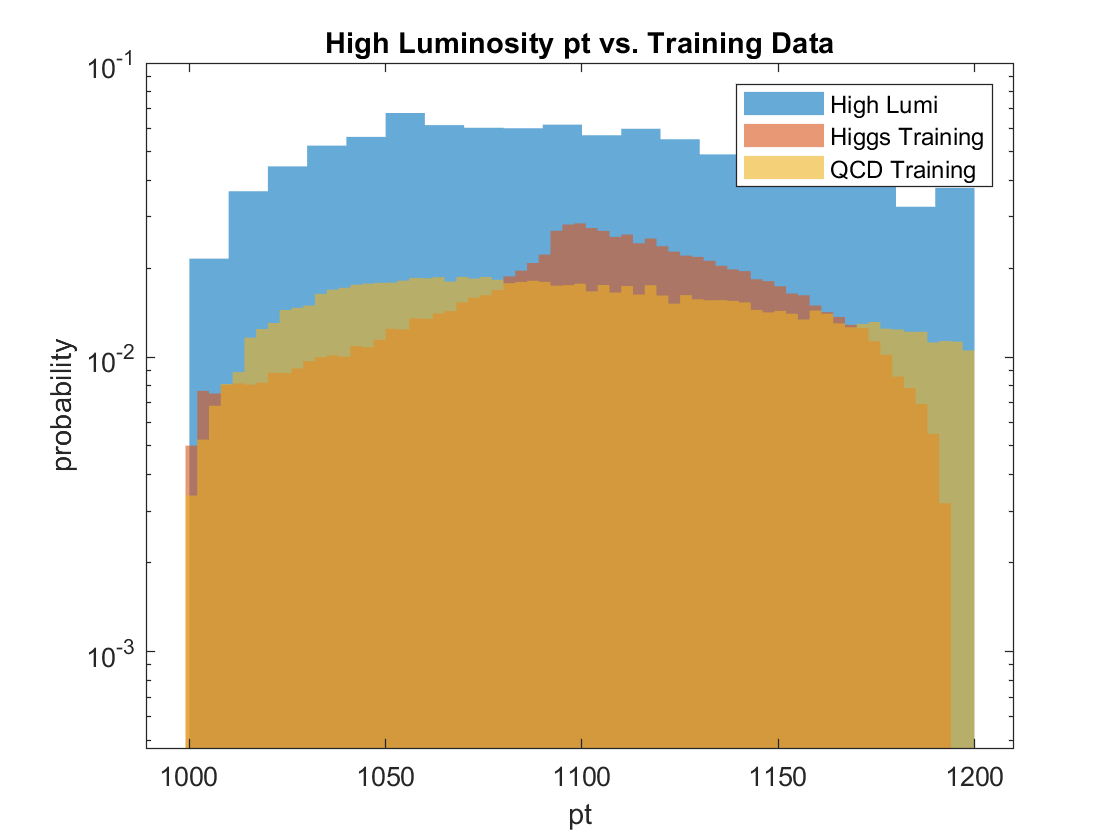

%pt
r = 1;
histogram(hlumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('pt')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity pt vs. Training Data')
hold off

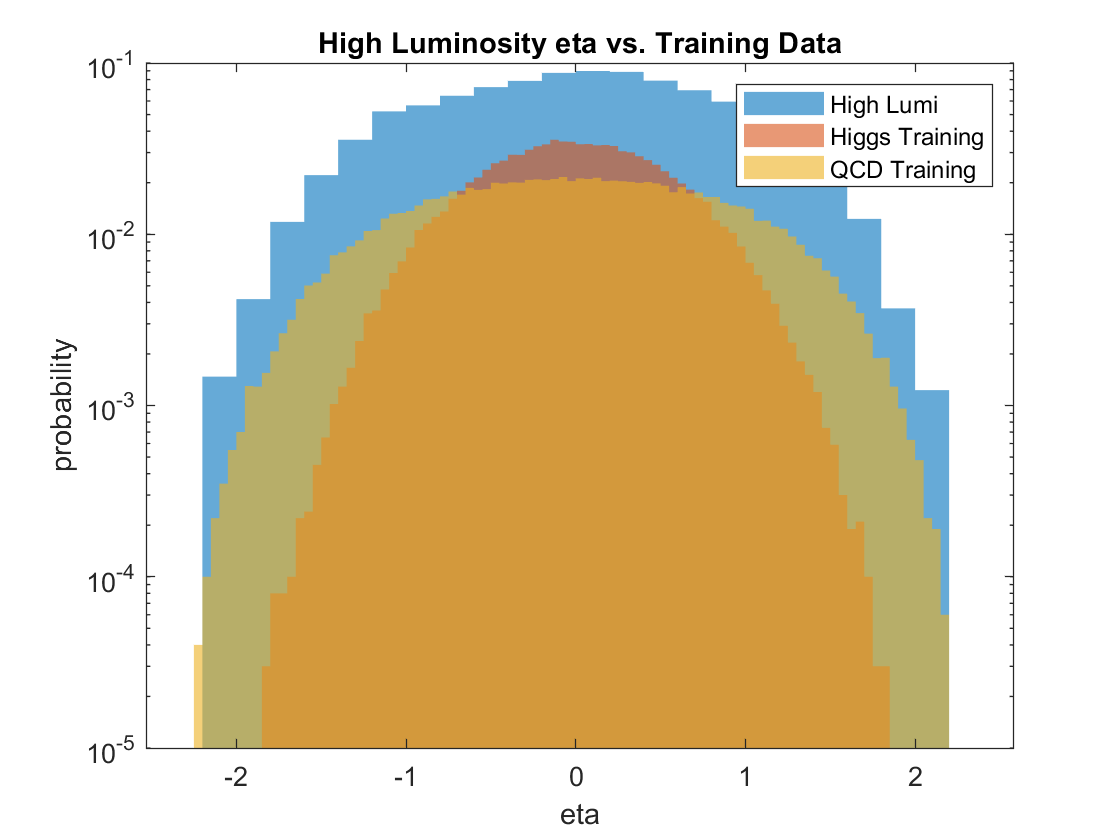

%eta
r = 2;
histogram(hlumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('eta')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity eta vs. Training Data')
hold off

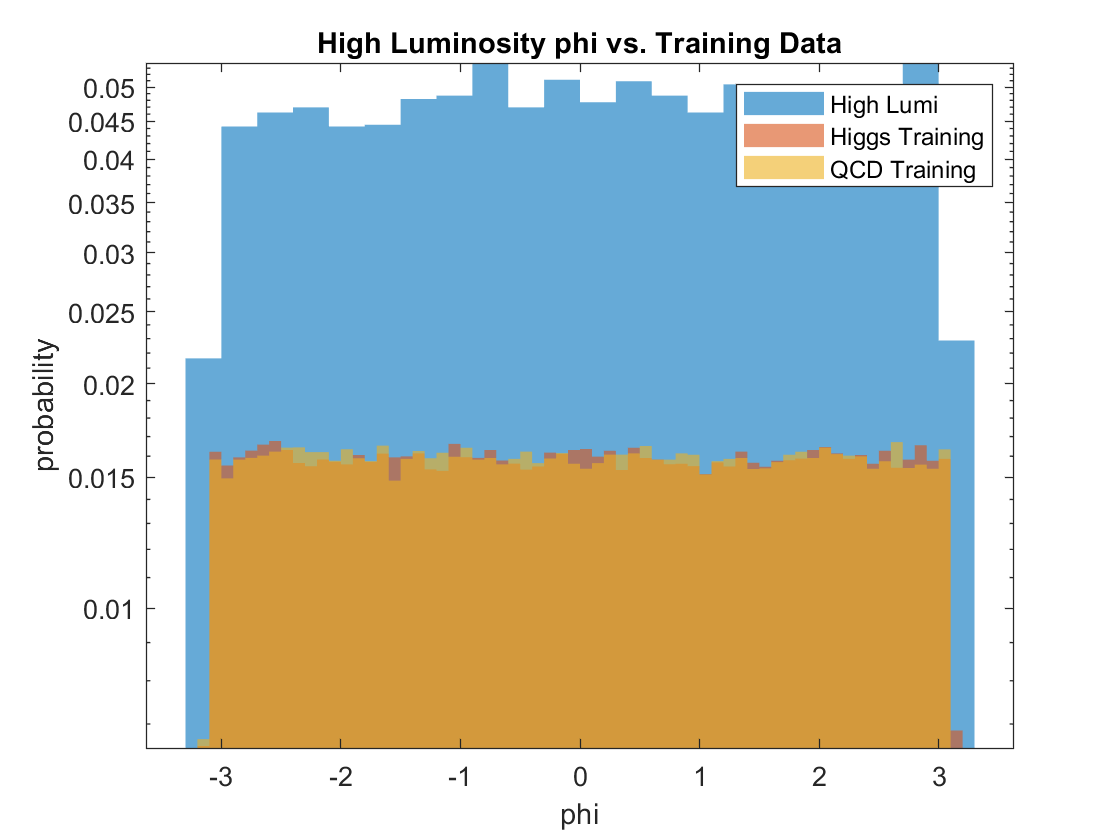

%phi
r = 3;
histogram(hlumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('phi')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity phi vs. Training Data')
hold off

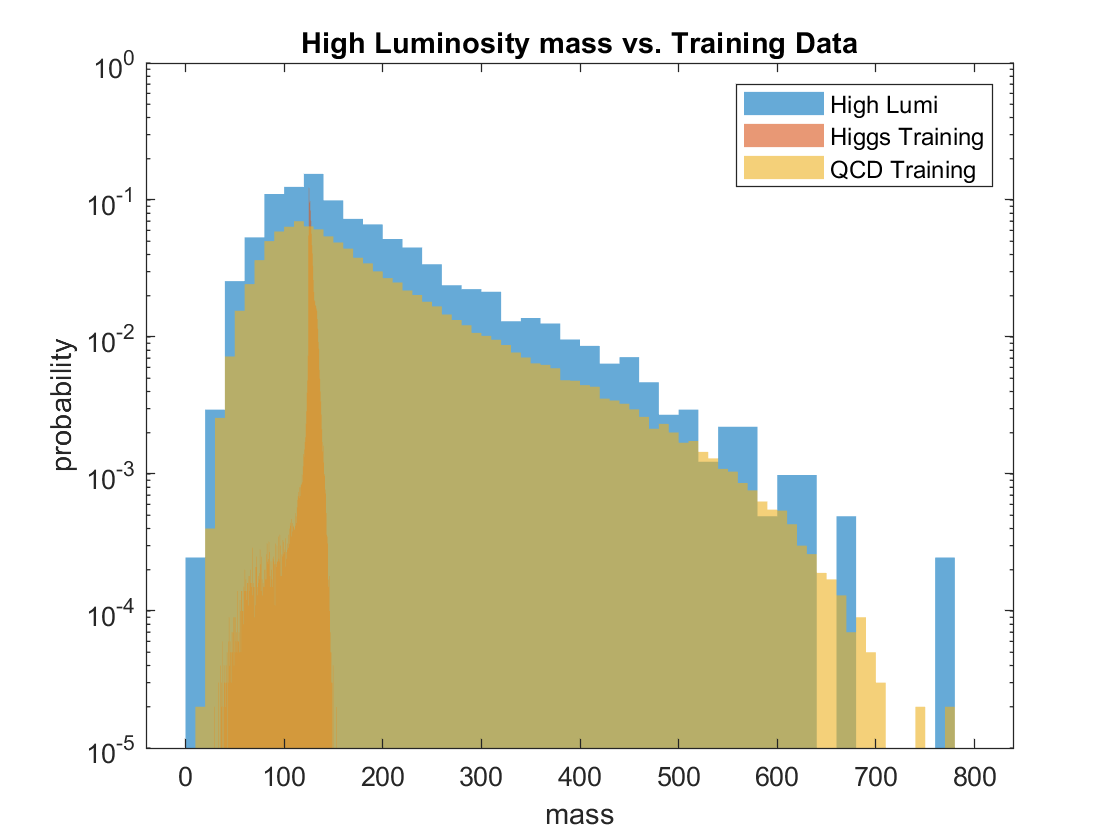

%mass
r = 4;
histogram(hlumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('mass')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity mass vs. Training Data')
hold off

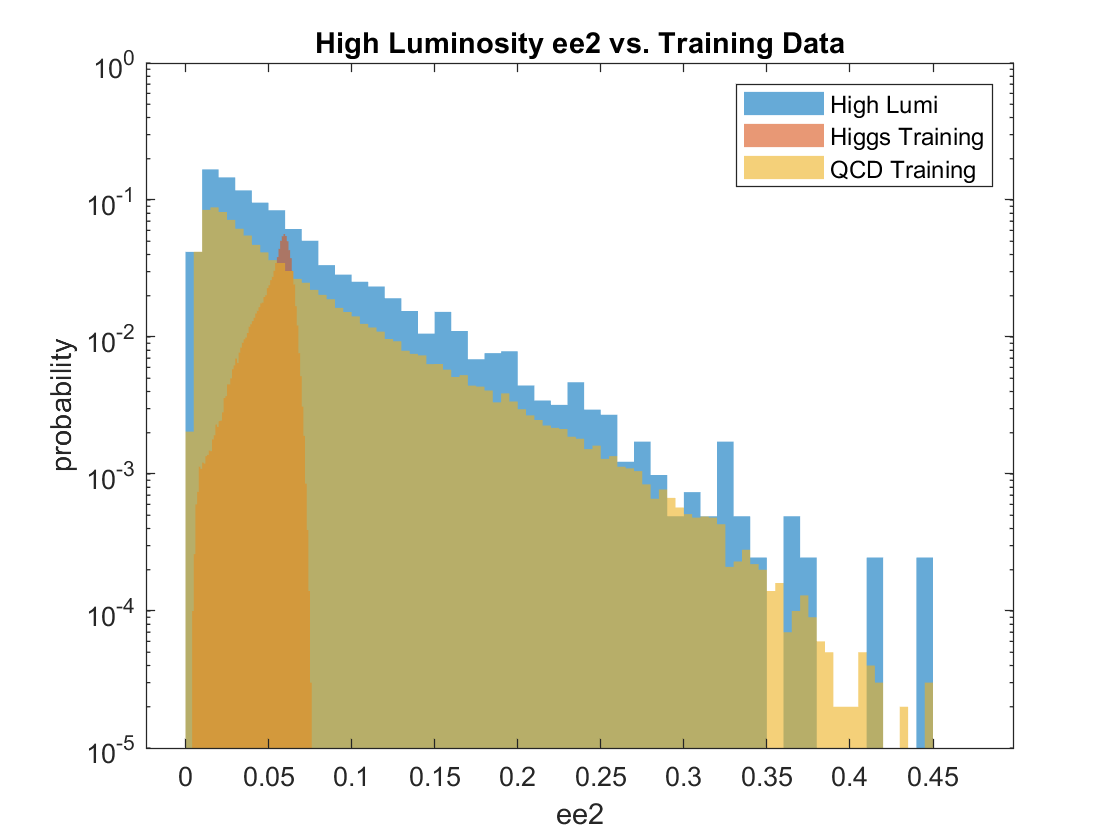

%ee2
r = 5;
histogram(hlumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('ee2')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity ee2 vs. Training Data')
hold off

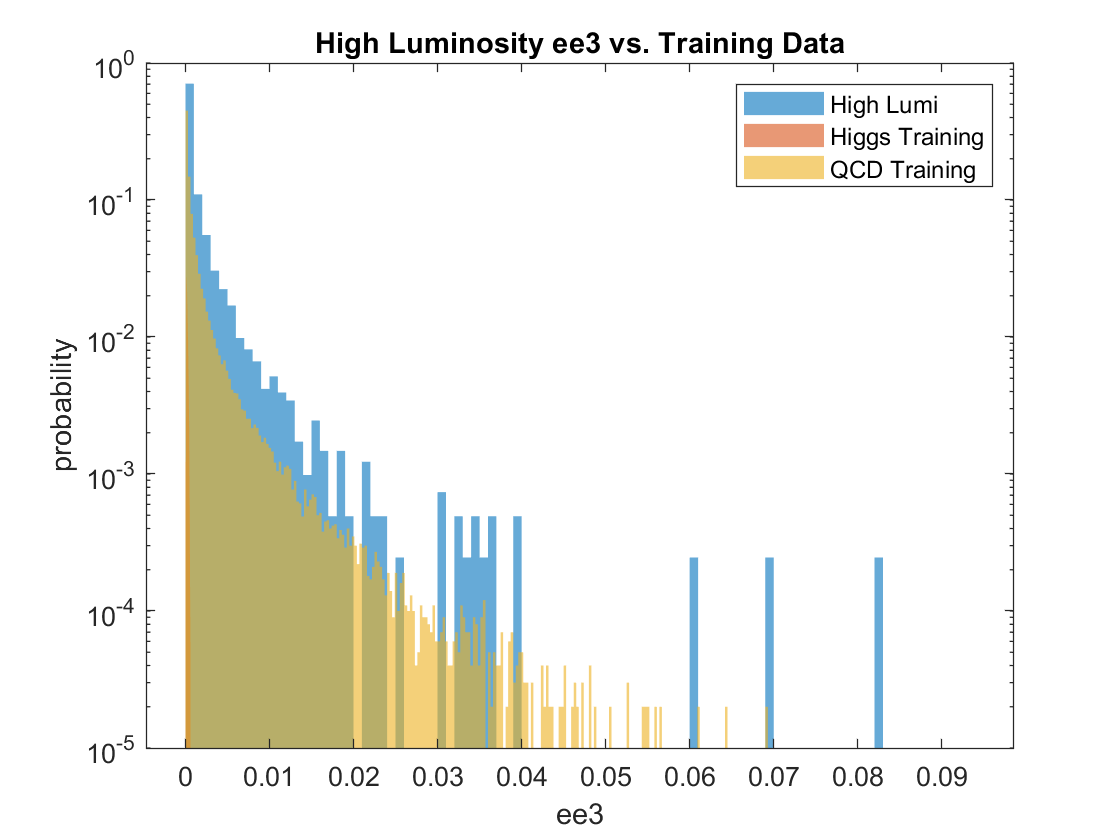

%ee3
r = 6;
histogram(hlumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('ee3')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity ee3 vs. Training Data')
hold off

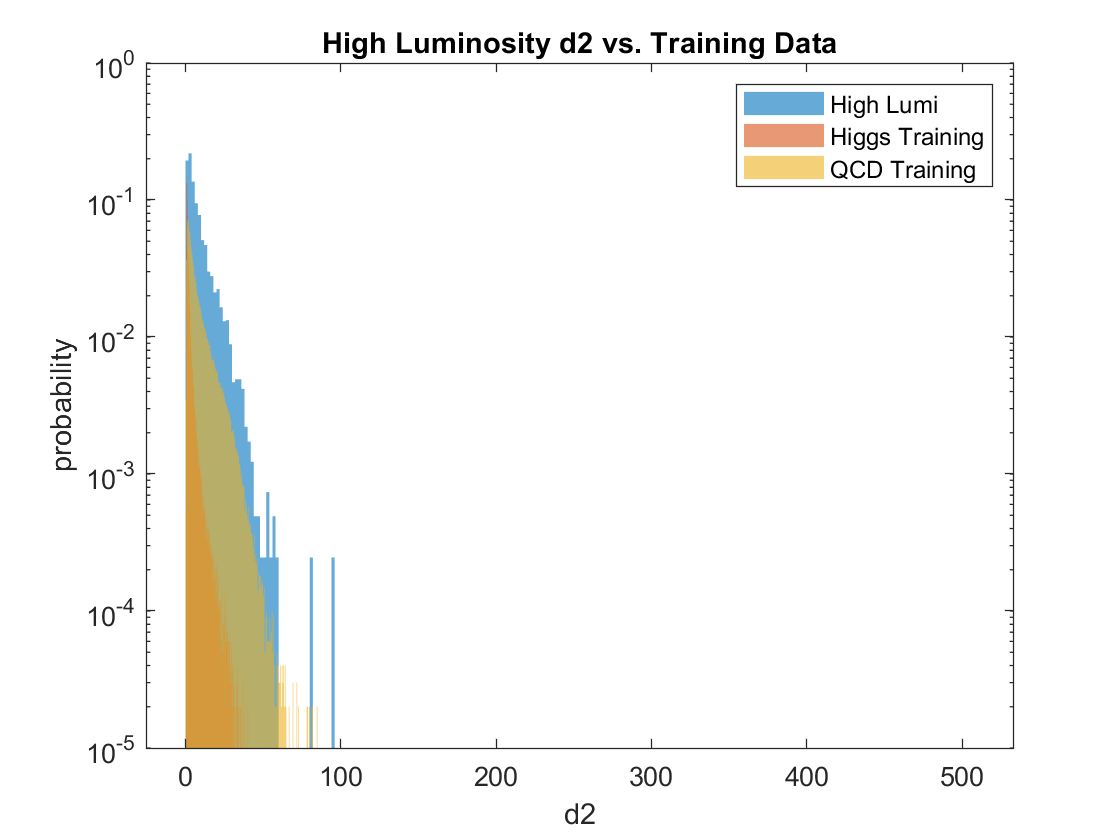

%d2
r = 7;
histogram(hlumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('d2')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity d2 vs. Training Data')
hold off

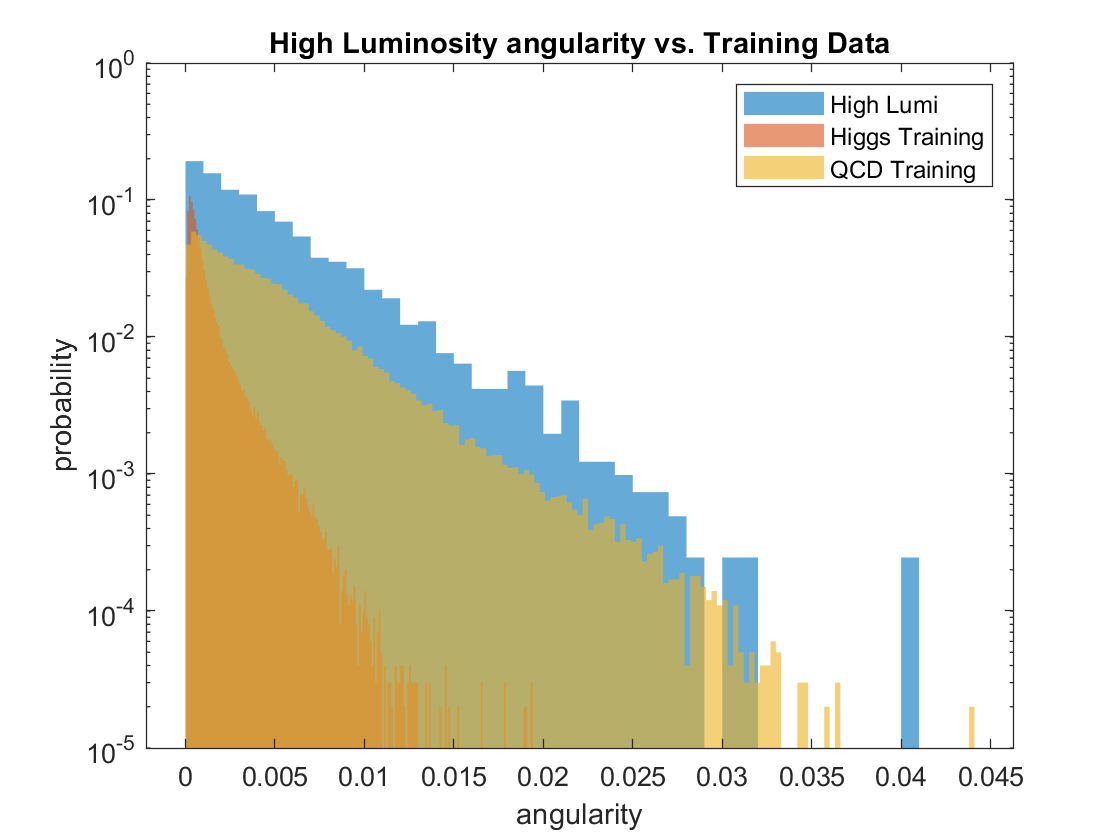

%angularity
r = 8;
histogram(hlumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('angularity')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity angularity vs. Training Data')
hold off

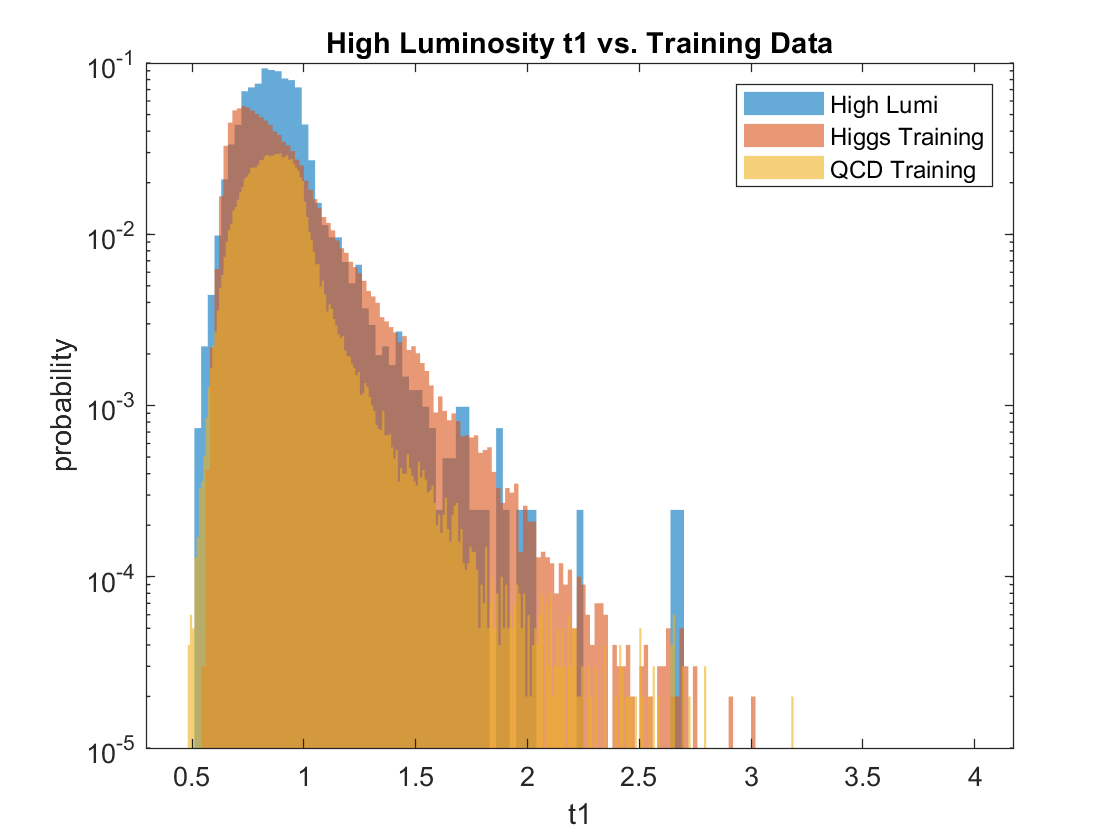

%t1
r = 9;
histogram(hlumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('t1')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity t1 vs. Training Data')
hold off

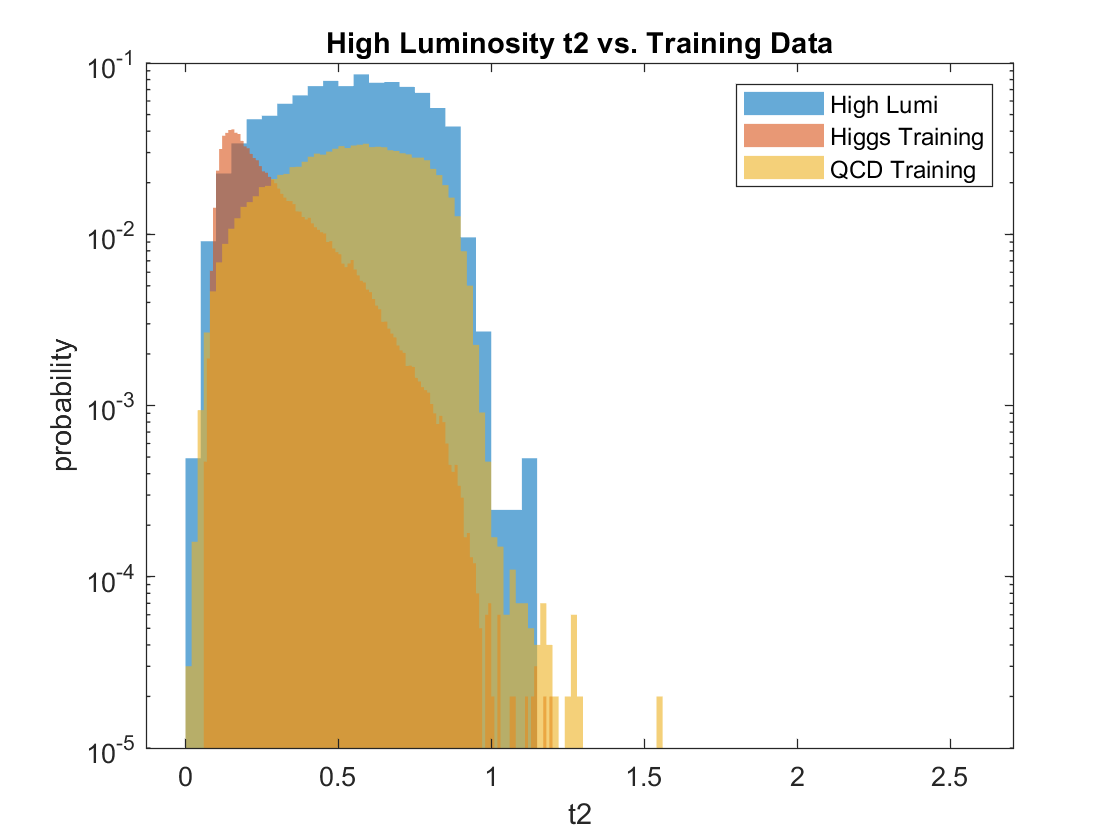

%t2
r = 10;
histogram(hlumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('t2')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity t2 vs. Training Data')
hold off

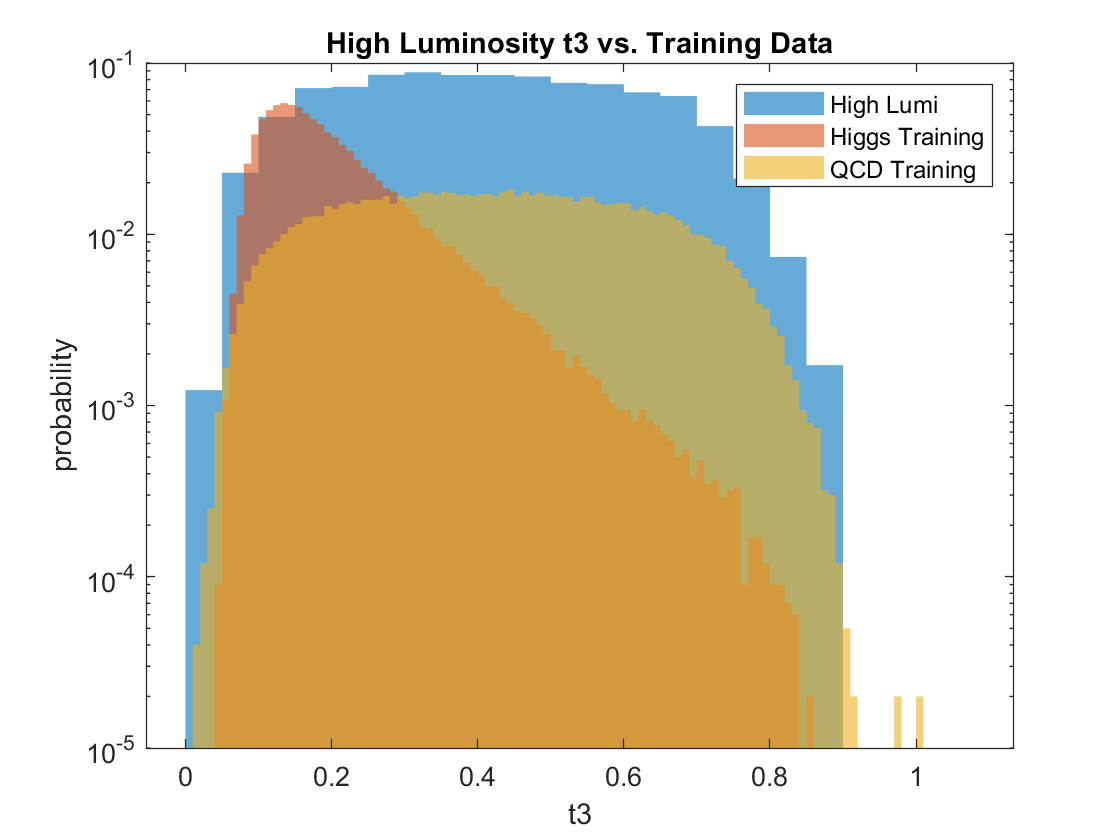

%t3
r = 11;
histogram(hlumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('t3')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity t3 vs. Training Data')
hold off

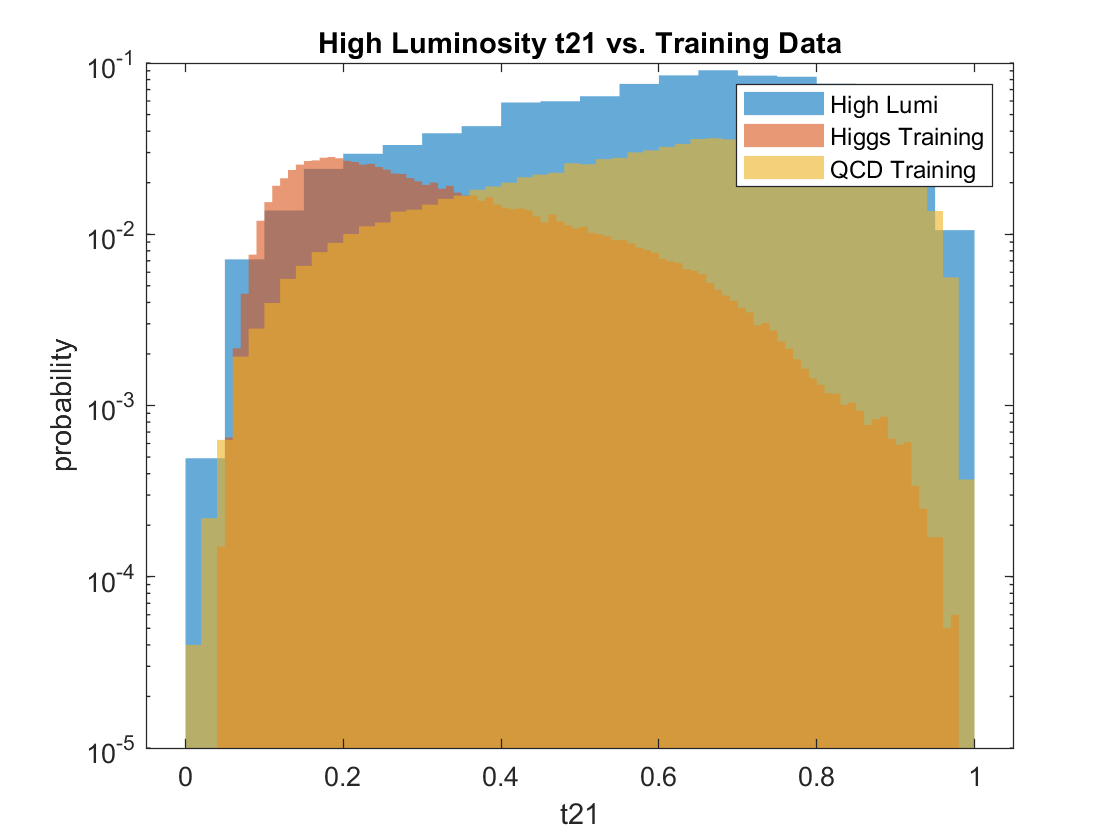

%t21
r = 12;
histogram(hlumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('t21')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity t21 vs. Training Data')
hold off

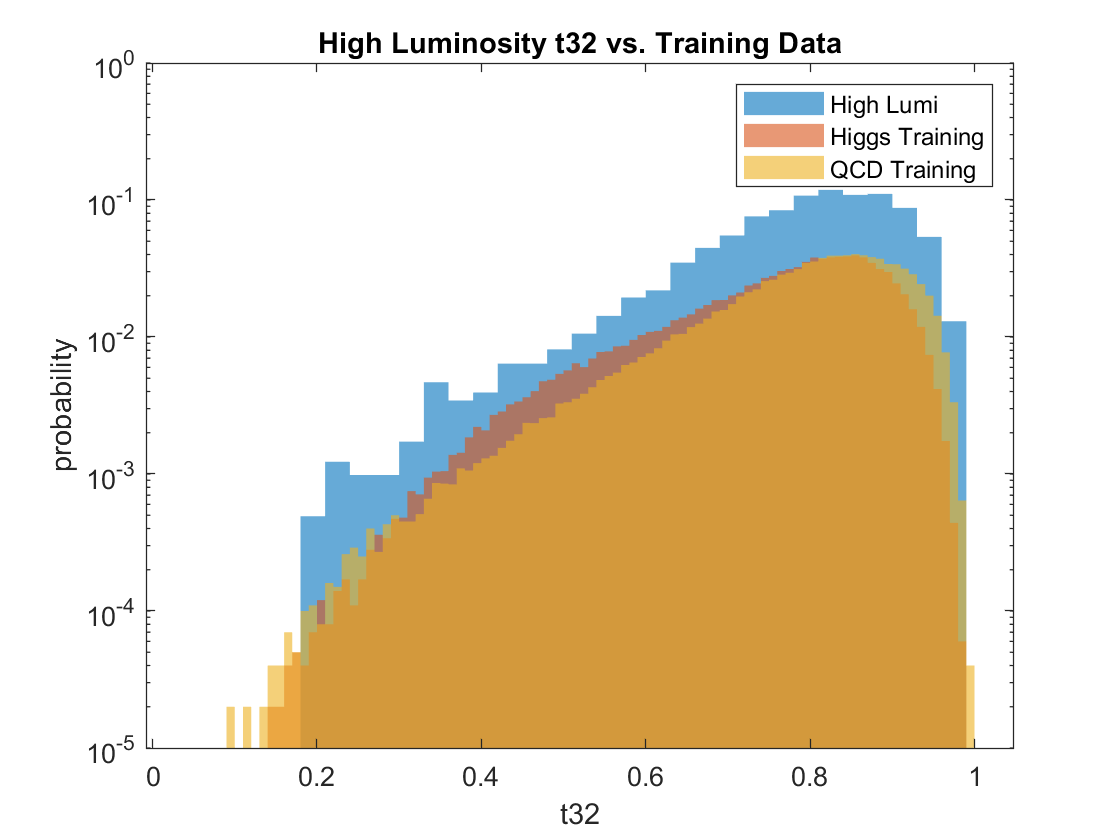

%t32
r = 13;
histogram(hlumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('t32')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity t32 vs. Training Data')
hold off

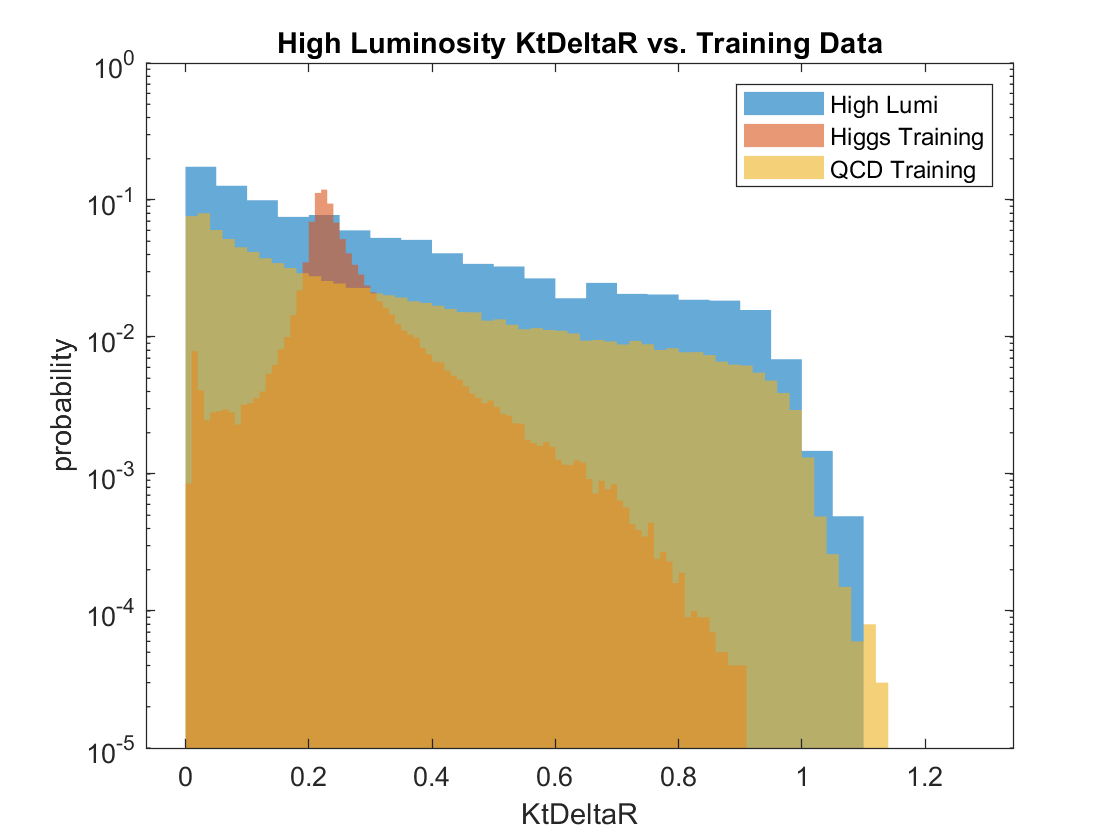

%KtDeltaR
r = 14;
histogram(hlumi(r,:),'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none')
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none')
set(gca,'Yscale','log')
xlabel('KtDeltaR')
ylabel('probability')
legend('High Lumi','Higgs Training','QCD Training')
title('High Luminosity KtDeltaR vs. Training Data')
hold off

- Plot observed data, overlap with expected signal and background (normalized to observed yields) without event selection.

- Plot observed data, overlap with expected signal and background (normalized to observed yields) with optimal event selection.

coordinates;
SIGh = zeros(2,14);

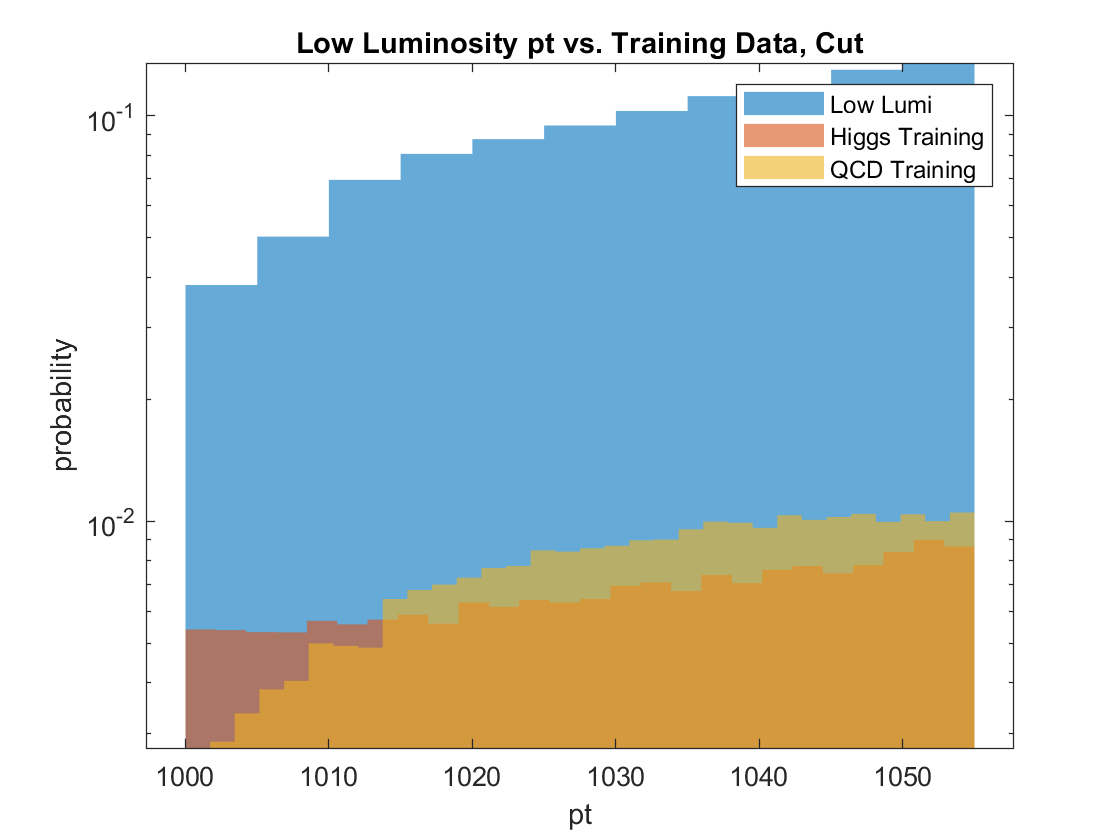

%pt
r = 1;
HL = zeros(1,4066);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:4066
    if (coordinates(r,1) < hlumi(r,i)) && (hlumi(r,i) < coordinates(r,2))
        HL(i) = hlumi(r,i);
    else
        HL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

hlc = rmmissing(HL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(hlc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('pt')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity pt vs. Training Data, Cut')
hold off


lhl = length(hlumi(r,:));
lhlc = length(hlc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lhl/lqcd;
N_sig = lhlc;

SIGh(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = Nback + N_sig;
pr = cdf(poiss,signal);
SIGh(r,2) = norminv(pr)

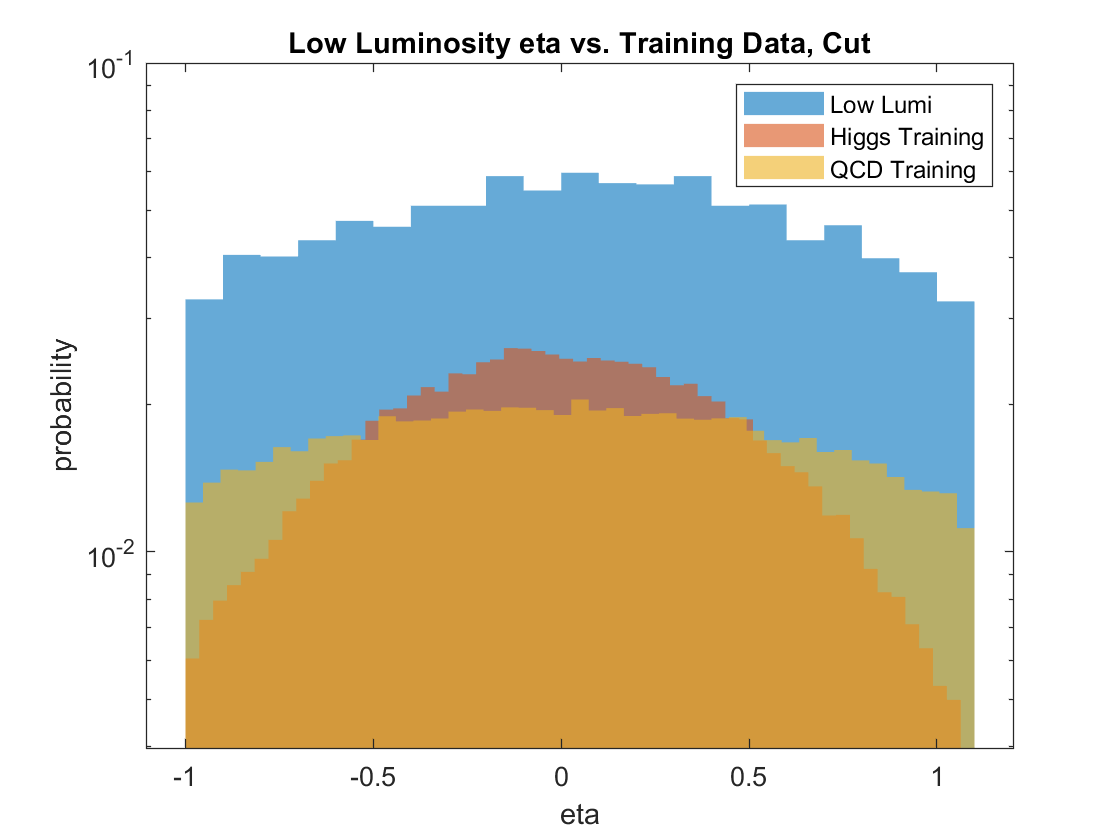

%eta
r = 2;
HL = zeros(1,4066);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:4066
    if (coordinates(r,1) < hlumi(r,i)) && (hlumi(r,i) < coordinates(r,2))
        HL(i) = hlumi(r,i);
    else
        HL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

hlc = rmmissing(HL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(hlc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('eta')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity eta vs. Training Data, Cut')
hold off


lhl = length(hlumi(r,:));
lhlc = length(hlc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lhl/lqcd;
N_sig = lhlc;

SIGh(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = Nback + N_sig;
pr = cdf(poiss,signal);
SIGh(r,2) = norminv(pr)

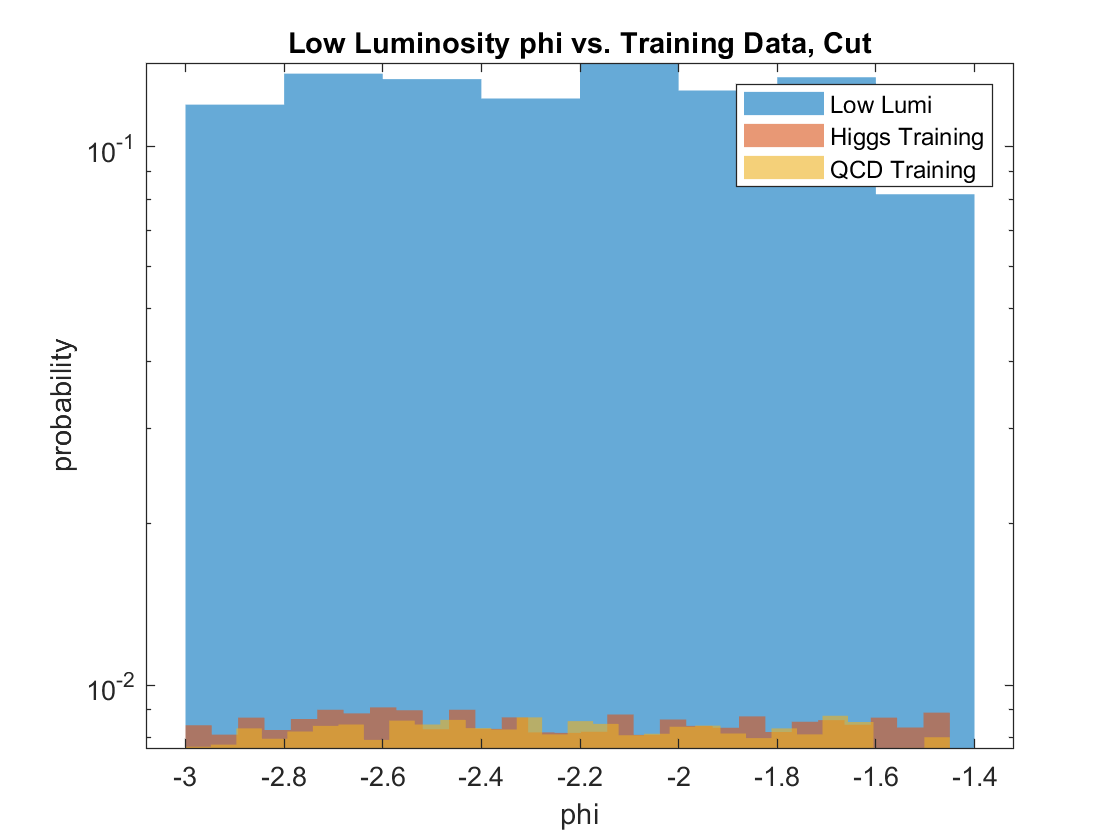

%phi
r = 3;
HL = zeros(1,4066);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:4066
    if (coordinates(r,1) < hlumi(r,i)) && (hlumi(r,i) < coordinates(r,2))
        HL(i) = hlumi(r,i);
    else
        HL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

hlc = rmmissing(HL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(hlc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('phi')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity phi vs. Training Data, Cut')
hold off


lhl = length(hlumi(r,:));
lhlc = length(hlc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lhl/lqcd;
N_sig = lhlc;

SIGh(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = Nback + N_sig;
pr = cdf(poiss,signal);
SIGh(r,2) = norminv(pr)

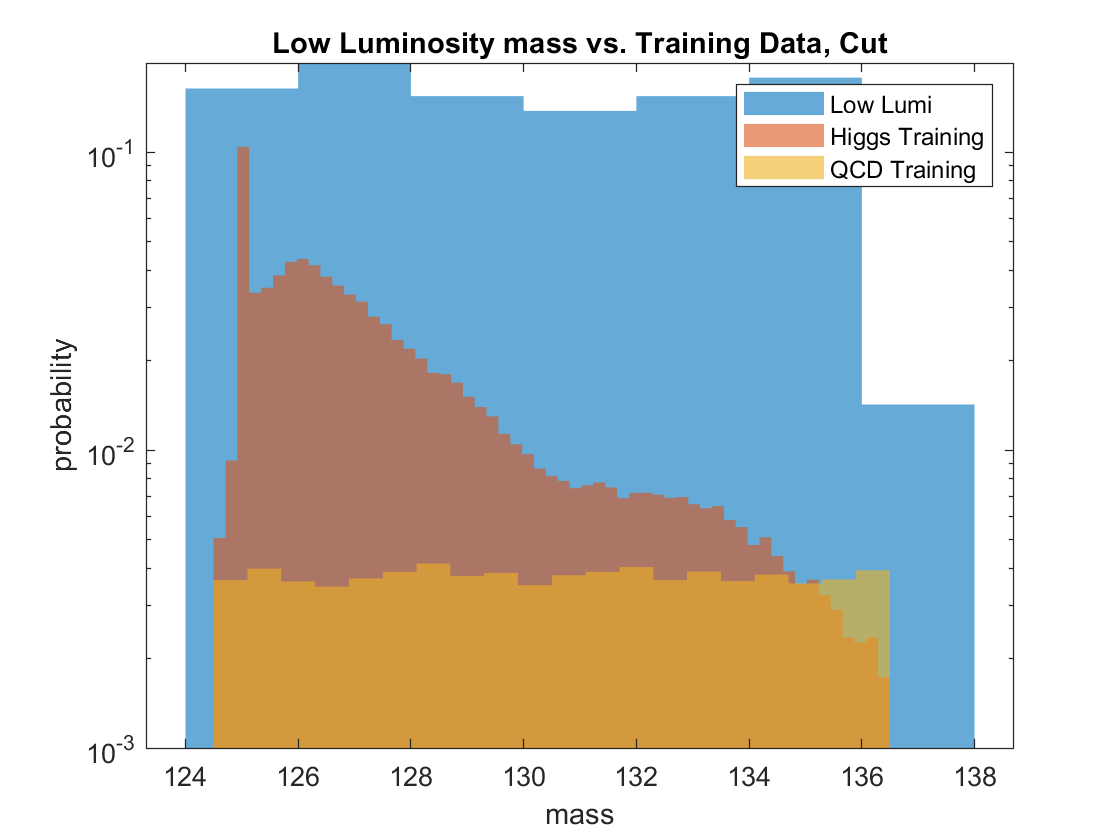

%mass
HL = zeros(1,4066);
r = 4;
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:4066
    if (coordinates(r,1) < hlumi(r,i)) && (hlumi(r,i) < coordinates(r,2))
        HL(i) = hlumi(r,i);
    else
        HL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

hlc = rmmissing(HL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(hlc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('mass')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity mass vs. Training Data, Cut')
hold off


lhl = length(hlumi(r,:));
lhlc = length(hlc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lhl/lqcd;
N_sig = lhlc;

SIGh(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = Nback + N_sig;
pr = cdf(poiss,signal);
SIGh(r,2) = norminv(pr)

sigma = Inf

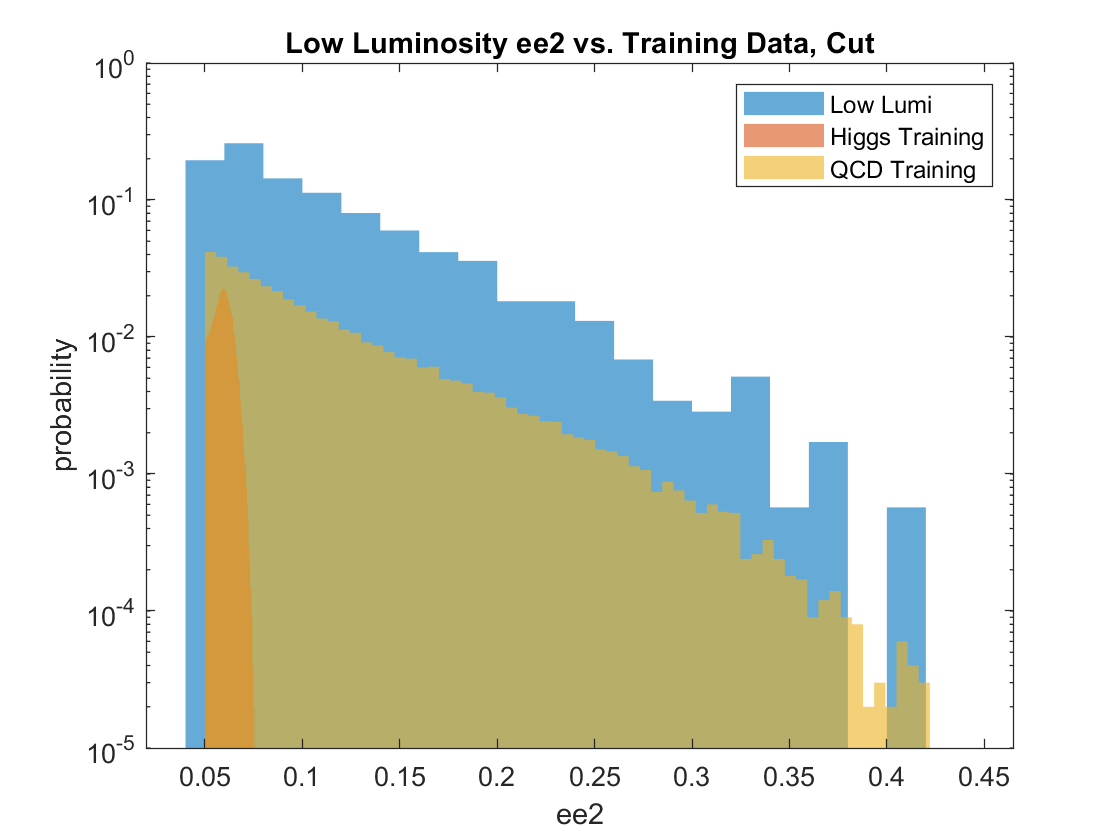

%ee2
r = 5;
HL = zeros(1,4066);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:4066
    if (coordinates(r,1) < hlumi(r,i)) && (hlumi(r,i) < coordinates(r,2))
        HL(i) = hlumi(r,i);
    else
        HL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

hlc = rmmissing(HL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(hlc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('ee2')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity ee2 vs. Training Data, Cut')
hold off


lhl = length(hlumi(r,:));
lhlc = length(hlc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lhl/lqcd;
N_sig = lhlc;

SIGh(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = Nback + N_sig;
pr = cdf(poiss,signal);
SIGh(r,2) = norminv(pr)

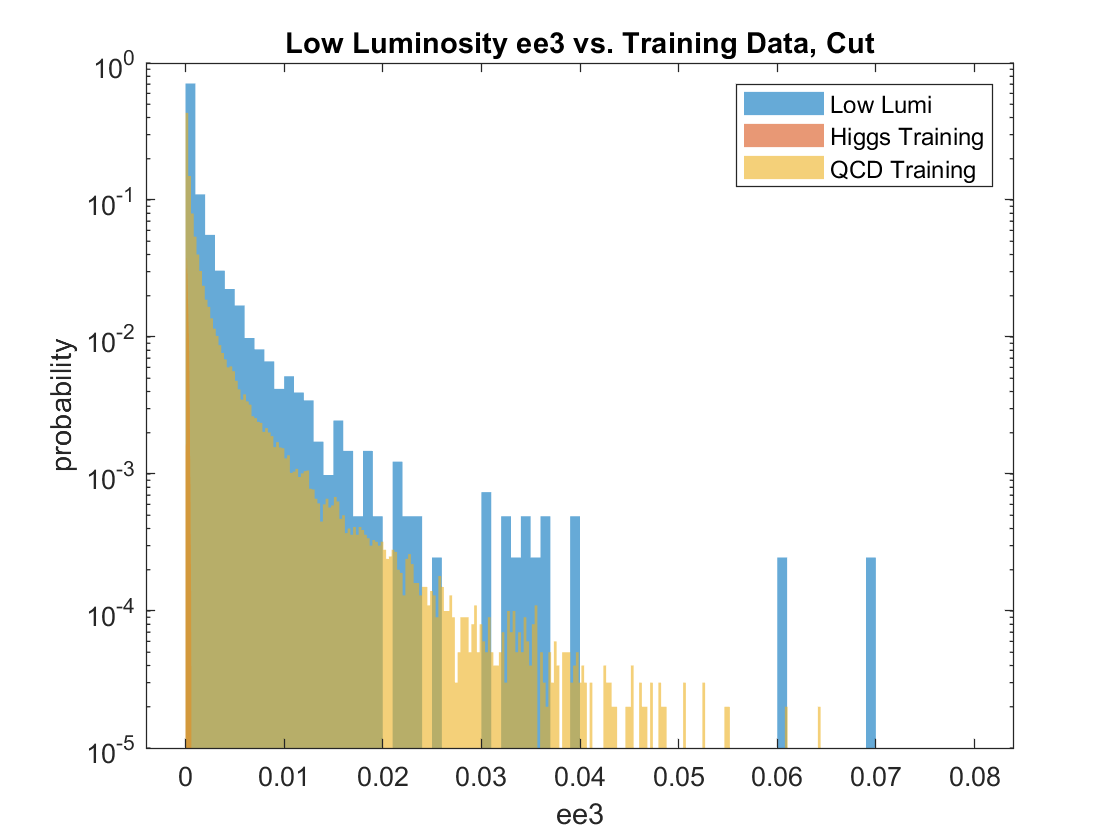

%ee3
r = 6;
HL = zeros(1,4066);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:4066
    if (coordinates(r,1) < hlumi(r,i)) && (hlumi(r,i) < coordinates(r,2))
        HL(i) = hlumi(r,i);
    else
        HL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

hlc = rmmissing(HL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(hlc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('ee3')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity ee3 vs. Training Data, Cut')
hold off


lhl = length(hlumi(r,:));
lhlc = length(hlc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lhl/lqcd;
N_sig = lhlc;

SIGh(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = Nback + N_sig;
pr = cdf(poiss,signal);
SIGh(r,2) = norminv(pr)

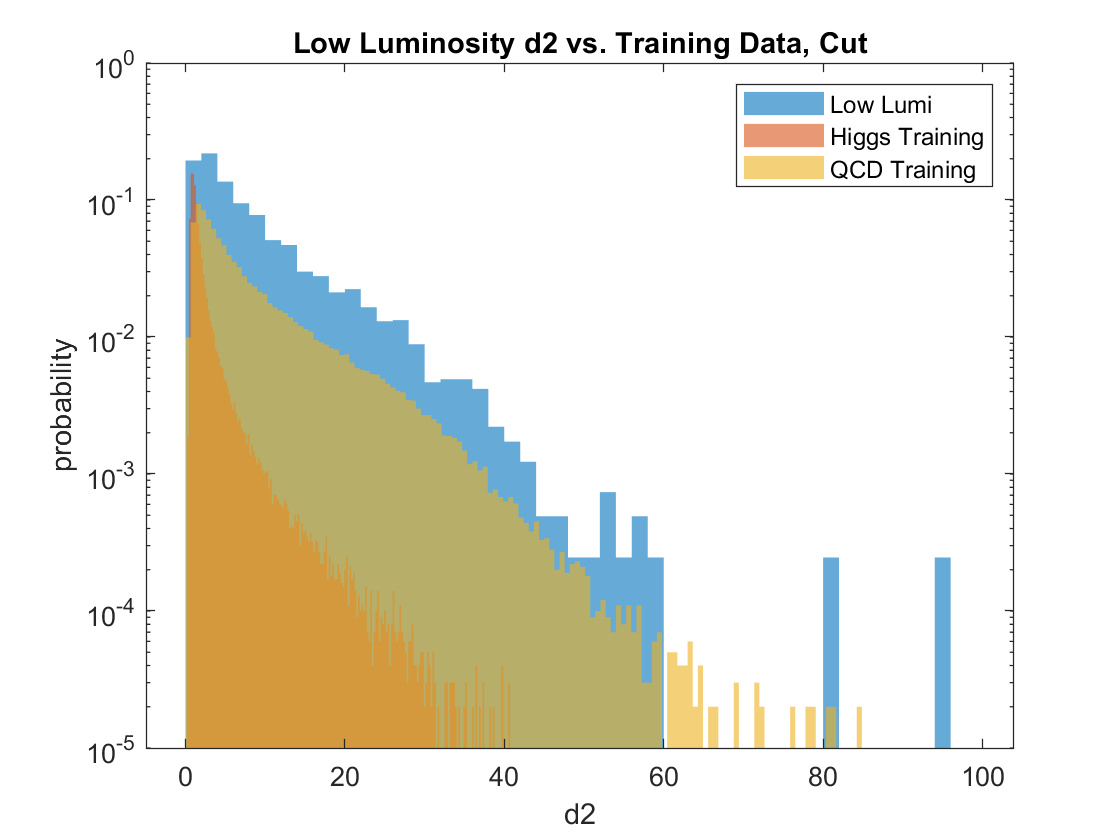

%d2
r = 7;
HL = zeros(1,4066);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:4066
    if (coordinates(r,1) < hlumi(r,i)) && (hlumi(r,i) < coordinates(r,2))
        HL(i) = hlumi(r,i);
    else
        HL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

hlc = rmmissing(HL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(hlc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('d2')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity d2 vs. Training Data, Cut')
hold off


lhl = length(hlumi(r,:));
lhlc = length(hlc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lhl/lqcd;
N_sig = lhlc;

SIGh(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = Nback + N_sig;
pr = cdf(poiss,signal);
SIGh(r,2) = norminv(pr)

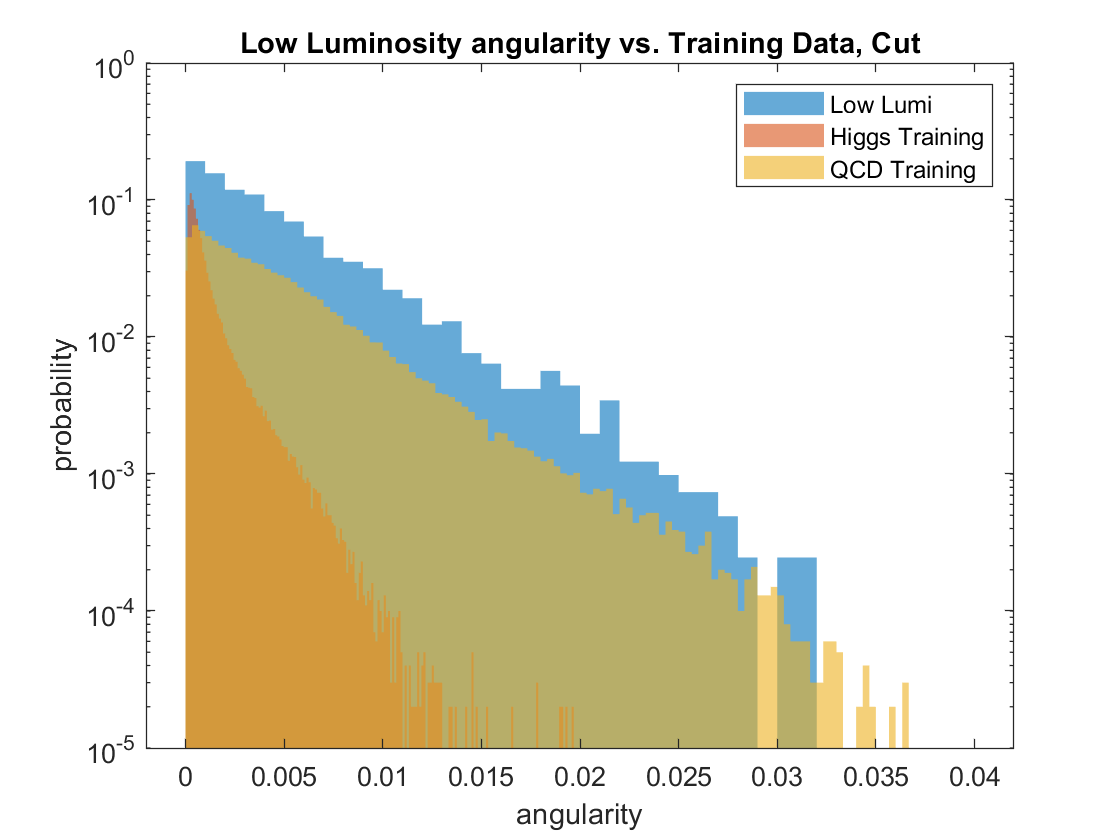

%angularity
r = 8;
HL = zeros(1,4066);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:4066
    if (coordinates(r,1) < hlumi(r,i)) && (hlumi(r,i) < coordinates(r,2))
        HL(i) = hlumi(r,i);
    else
        HL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

hlc = rmmissing(HL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(hlc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('angularity')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity angularity vs. Training Data, Cut')
hold off


lhl = length(hlumi(r,:));
lhlc = length(hlc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lhl/lqcd;
N_sig = lhlc;

SIGh(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = Nback + N_sig;
pr = cdf(poiss,signal);
SIGh(r,2) = norminv(pr)

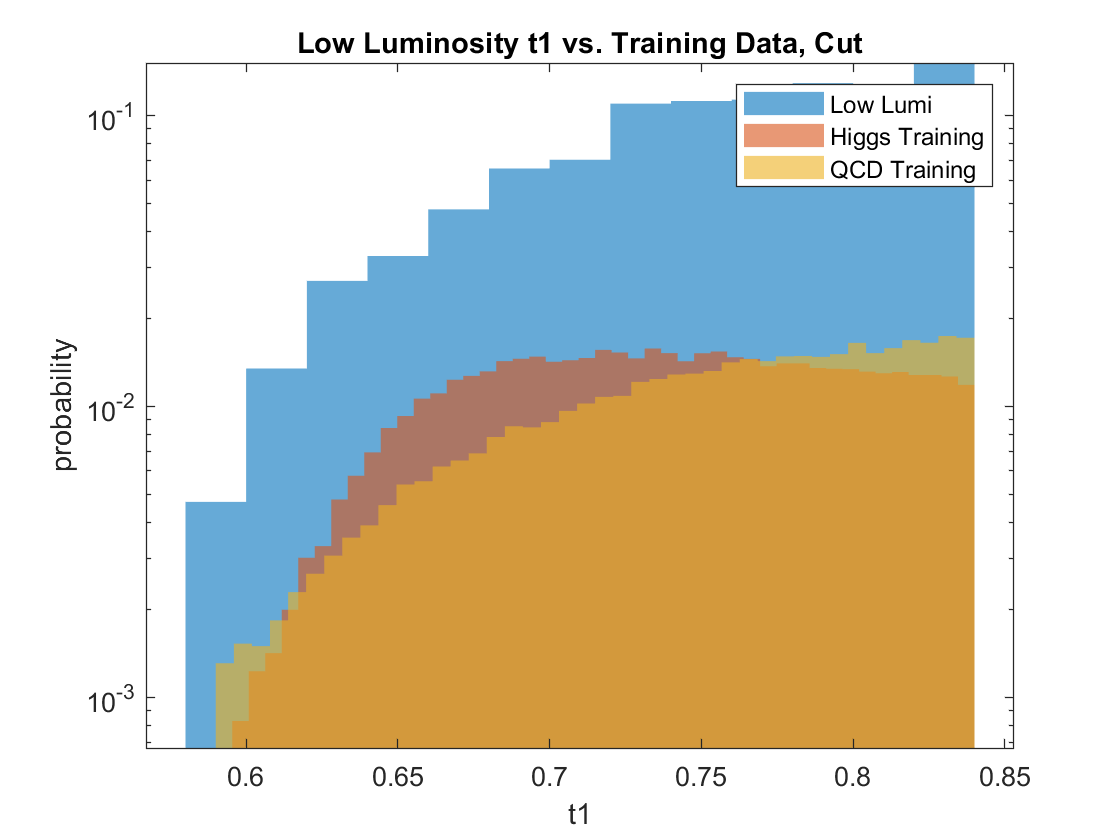

%t1
r = 9;
HL = zeros(1,4066);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:4066
    if (coordinates(r,1) < hlumi(r,i)) && (hlumi(r,i) < coordinates(r,2))
        HL(i) = hlumi(r,i);
    else
        HL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

hlc = rmmissing(HL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(hlc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('t1')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity t1 vs. Training Data, Cut')
hold off


lhl = length(hlumi(r,:));
lhlc = length(hlc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lhl/lqcd;
N_sig = lhlc;

SIGh(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = Nback + N_sig;
pr = cdf(poiss,signal);
SIGh(r,2) = norminv(pr)

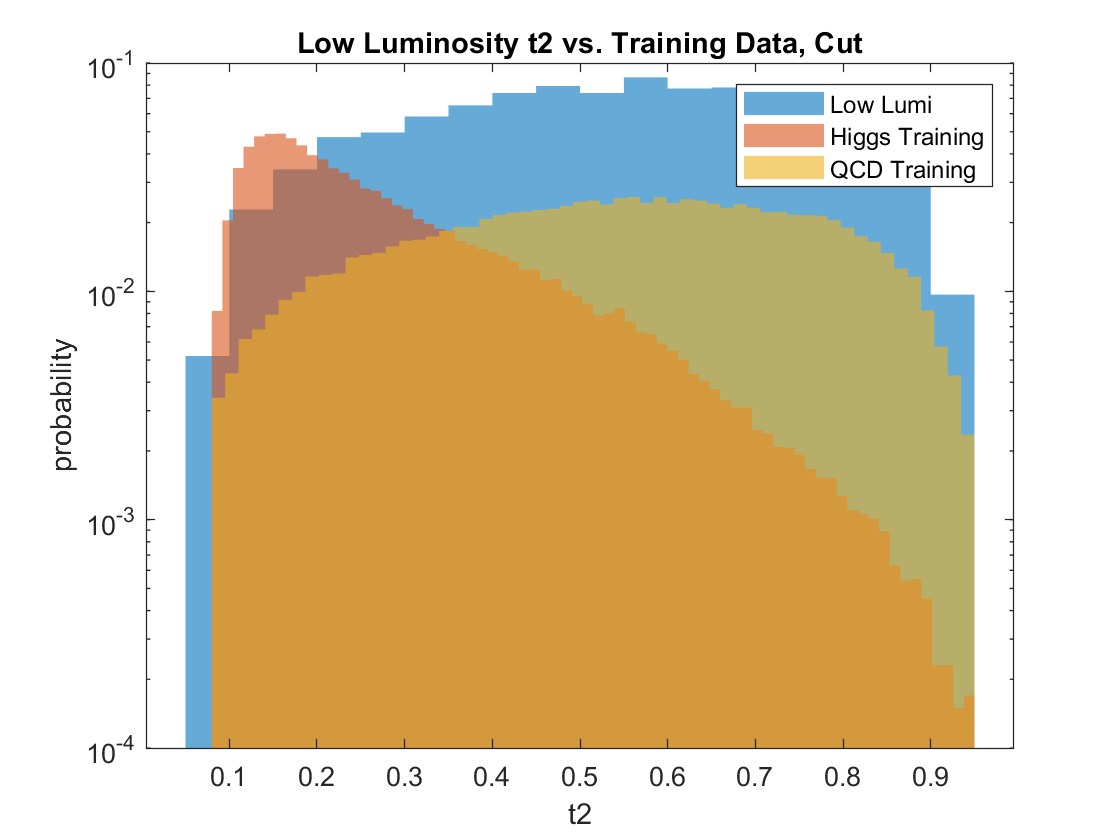

%t2
r = 10;
HL = zeros(1,4066);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:4066
    if (coordinates(r,1) < hlumi(r,i)) && (hlumi(r,i) < coordinates(r,2))
        HL(i) = hlumi(r,i);
    else
        HL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

hlc = rmmissing(HL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(hlc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('t2')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity t2 vs. Training Data, Cut')
hold off


lhl = length(hlumi(r,:));
lhlc = length(hlc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lhl/lqcd;
N_sig = lhlc;

SIGh(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = Nback + N_sig;
pr = cdf(poiss,signal);
SIGh(r,2) = norminv(pr)

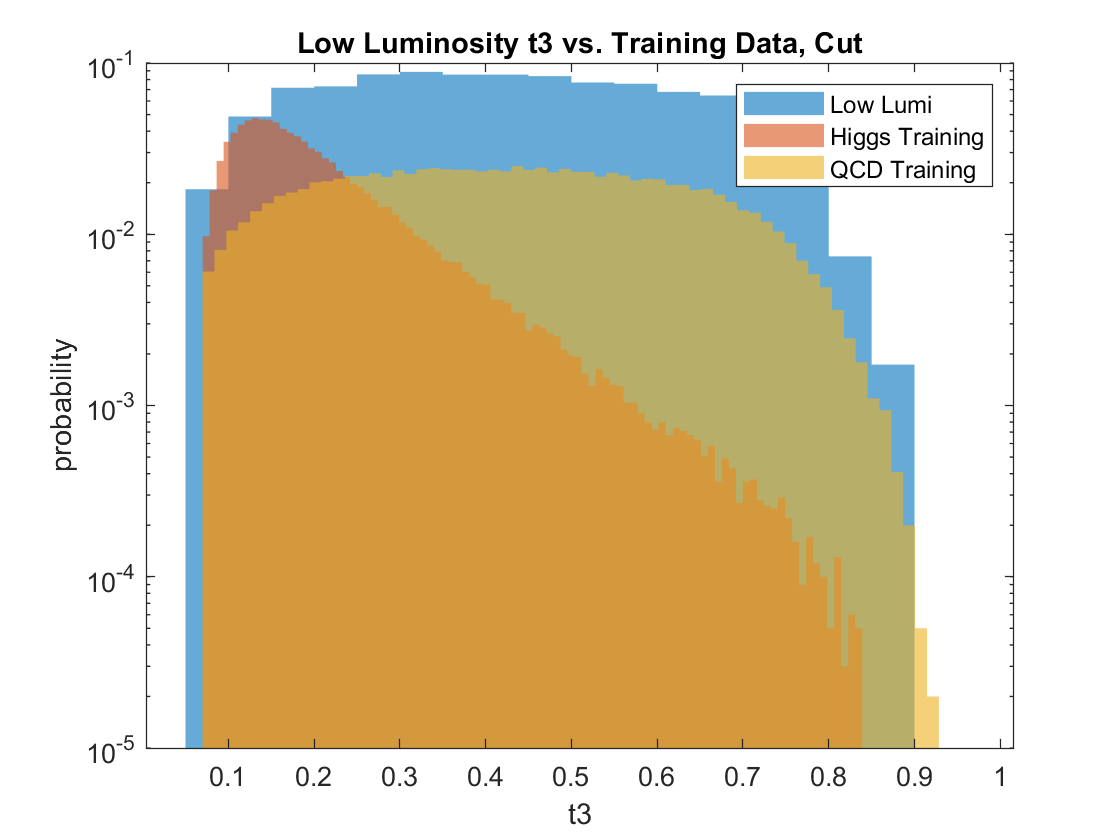

%t3
r = 11;
HL = zeros(1,4066);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:4066
    if (coordinates(r,1) < hlumi(r,i)) && (hlumi(r,i) < coordinates(r,2))
        HL(i) = hlumi(r,i);
    else
        HL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

hlc = rmmissing(HL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(hlc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('t3')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity t3 vs. Training Data, Cut')
hold off


lhl = length(hlumi(r,:));
lhlc = length(hlc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lhl/lqcd;
N_sig = lhlc;

SIGh(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = Nback + N_sig;
pr = cdf(poiss,signal);
SIGh(r,2) = norminv(pr)

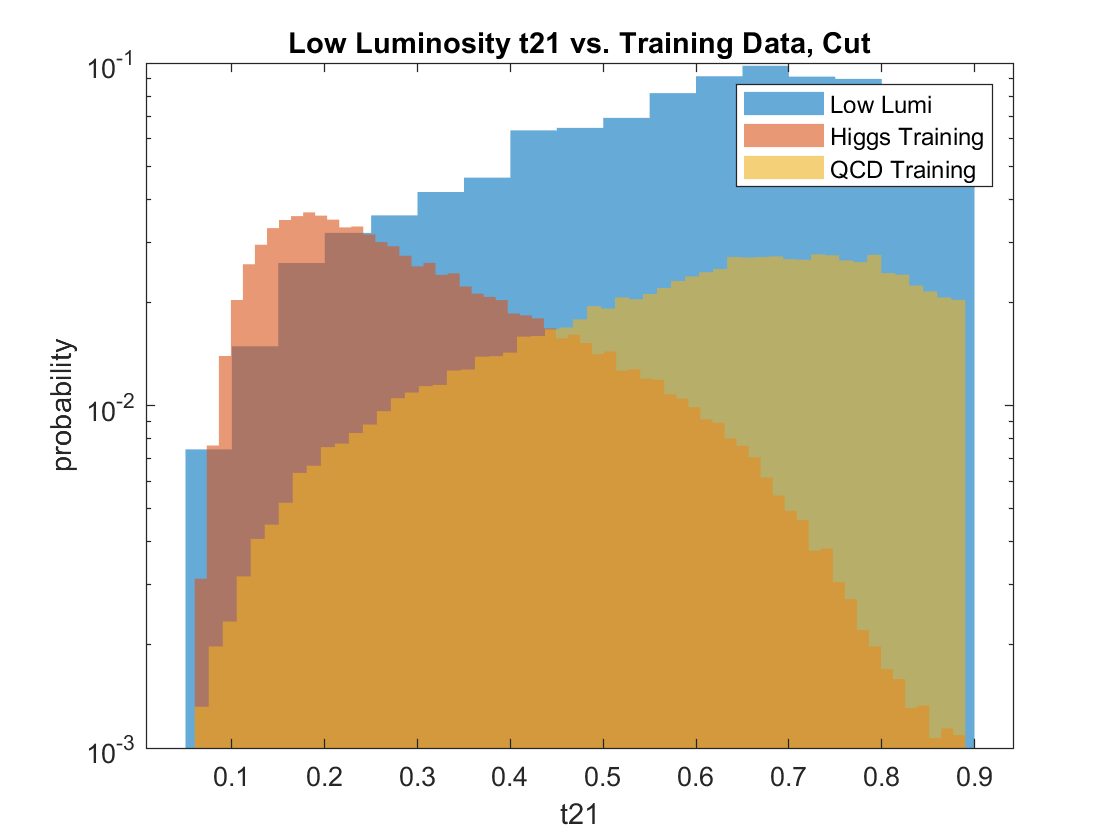

%t21
r = 12;
HL = zeros(1,4066);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:4066
    if (coordinates(r,1) < hlumi(r,i)) && (hlumi(r,i) < coordinates(r,2))
        HL(i) = hlumi(r,i);
    else
        HL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

hlc = rmmissing(HL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(hlc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('t21')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity t21 vs. Training Data, Cut')
hold off


lhl = length(hlumi(r,:));
lhlc = length(hlc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lhl/lqcd;
N_sig = lhlc;

SIGh(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = Nback + N_sig;
pr = cdf(poiss,signal);
SIGh(r,2) = norminv(pr)

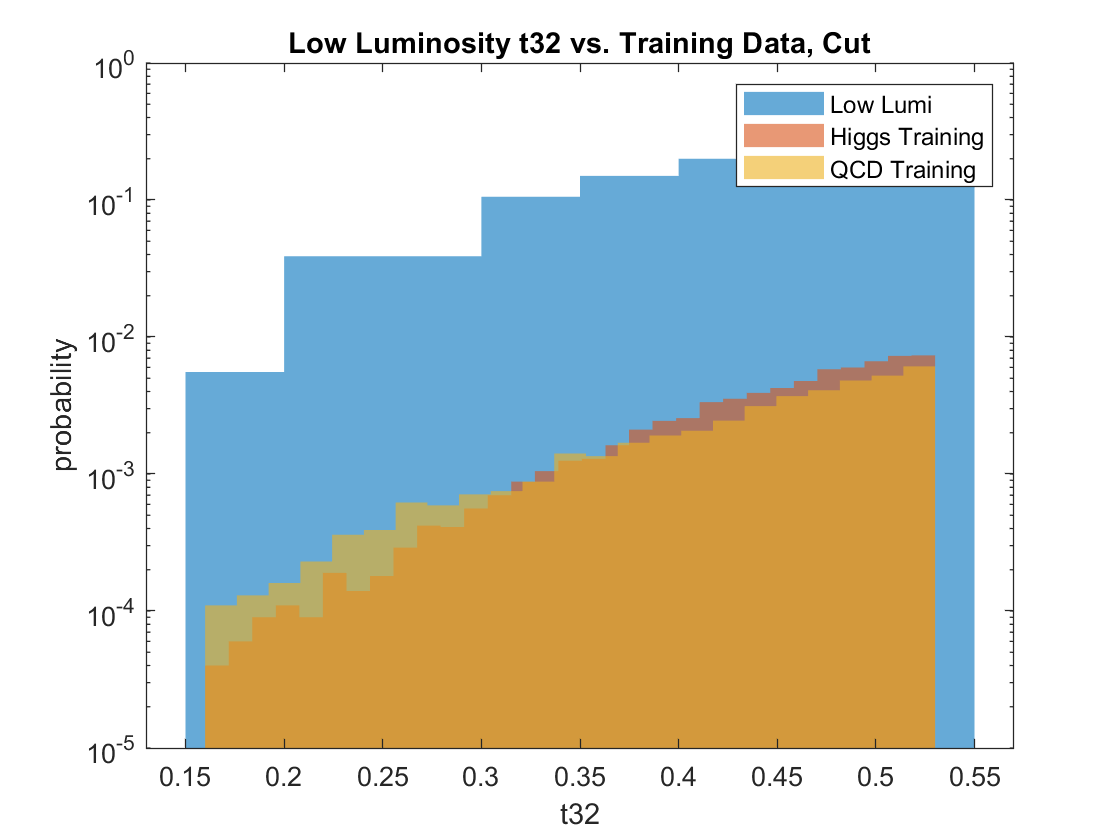

%t32
r = 13;
HL = zeros(1,4066);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:4066
    if (coordinates(r,1) < hlumi(r,i)) && (hlumi(r,i) < coordinates(r,2))
        HL(i) = hlumi(r,i);
    else
        HL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

hlc = rmmissing(HL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(hlc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('t32')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity t32 vs. Training Data, Cut')
hold off


lhl = length(hlumi(r,:));
lhlc = length(hlc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lhl/lqcd;
N_sig = lhlc;

SIGh(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = Nback + N_sig;
pr = cdf(poiss,signal);
SIGh(r,2) = norminv(pr)

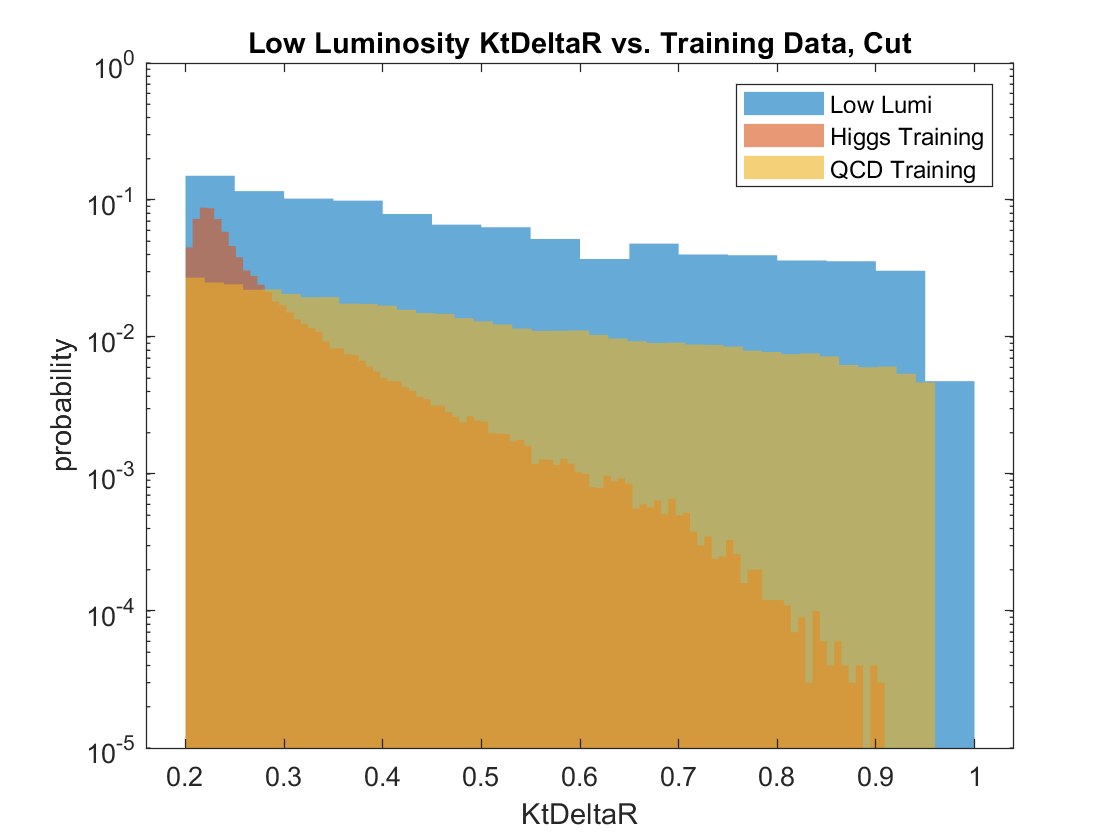

%KtDeltaR
r = 14;
HL = zeros(1,4066);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:4066
    if (coordinates(r,1) < hlumi(r,i)) && (hlumi(r,i) < coordinates(r,2))
        HL(i) = hlumi(r,i);
    else
        HL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

hlc = rmmissing(HL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(hlc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('KtDeltaR')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity KtDeltaR vs. Training Data, Cut')
hold off


lhl = length(hlumi(r,:));
lhlc = length(hlc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lhl/lqcd;
N_sig = lhlc;

SIGh(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = Nback + N_sig;
pr = cdf(poiss,signal);
SIGh(r,2) = norminv(pr)

SIGh

SIGh =     0.3892   22.4881         0         0         0         0         0         0         0         0         0         0         0         0
    1.2047   40.2345         0         0         0         0         0         0         0         0         0         0         0         0
    0.5574   21.3856         0         0         0         0         0         0         0         0         0         0         0         0
    3.6885   34.3033         0         0         0         0         0         0         0         0         0         0         0         0
    1.1567   30.3354         0         0         0         0         0         0         0         0         0         0         0         0
    1.1180   45.8286         0         0         0         0         0         0         0         0         0         0         0         0
    1.1181   45.8403         0         0         0         0         0         0         0         0         0         0         0         0
    1.

- Evaluate observed significance and compare your results to expectation

-     row one of SIGh is expectation; row two is observed. 

2)Low luminosity data

- Focus on each feature of your event selection.

- Plot observed data, overlap with expected signal and background (normalized to observed yields) without event selection.

- Plot observed data, overlap with expected signal and background (normalized to observed yields) with optimal event selection.

- Evaluate observed significance and compare your results to expectation

coordinates;
SIGl = zeros(2,14);

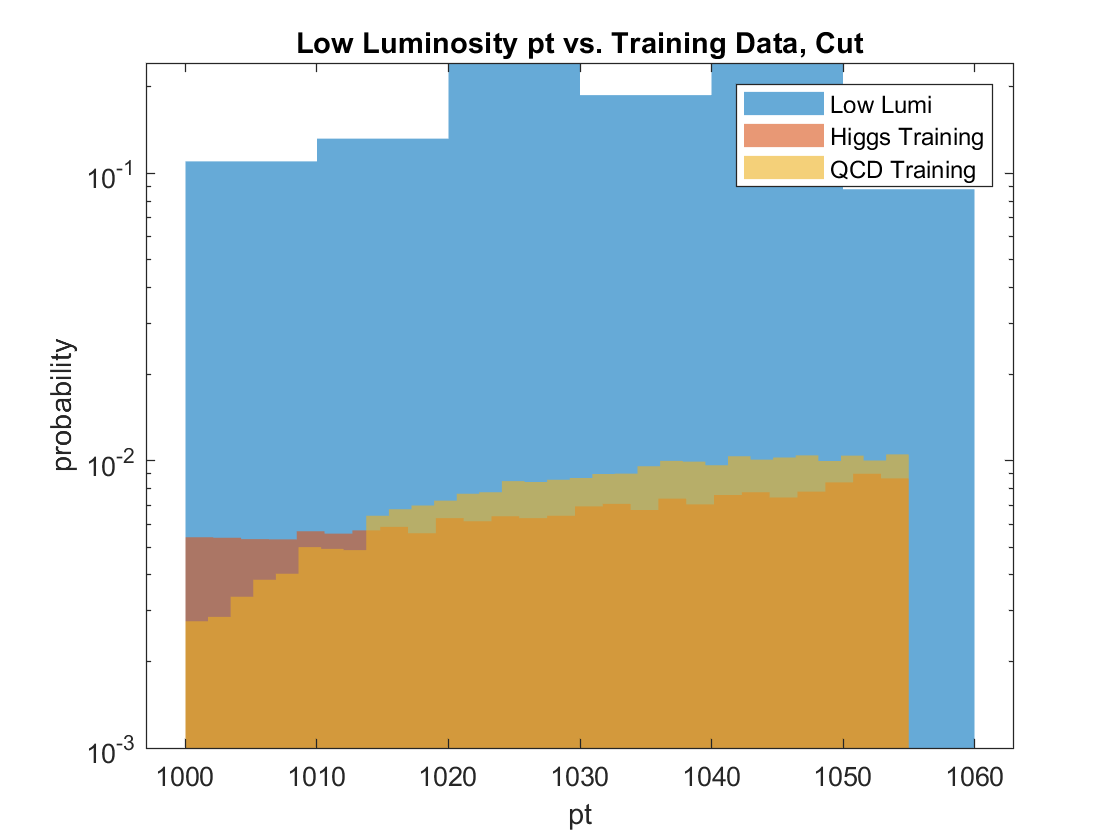

%pt
r = 1;
LL = zeros(1,442);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:442
    if (coordinates(r,1) < llumi(r,i)) && (llumi(r,i) < coordinates(r,2))
        LL(i) = llumi(r,i);
    else
        LL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

llc = rmmissing(LL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(llc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('pt')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity pt vs. Training Data, Cut')
hold off


lll = length(llumi(r,:));
lllc = length(llc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lll/lqcd;
N_sig = lllc;

SIGl(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = Nback + N_sig;
pr = cdf(poiss,signal);
SIGl(r,2) = norminv(pr)

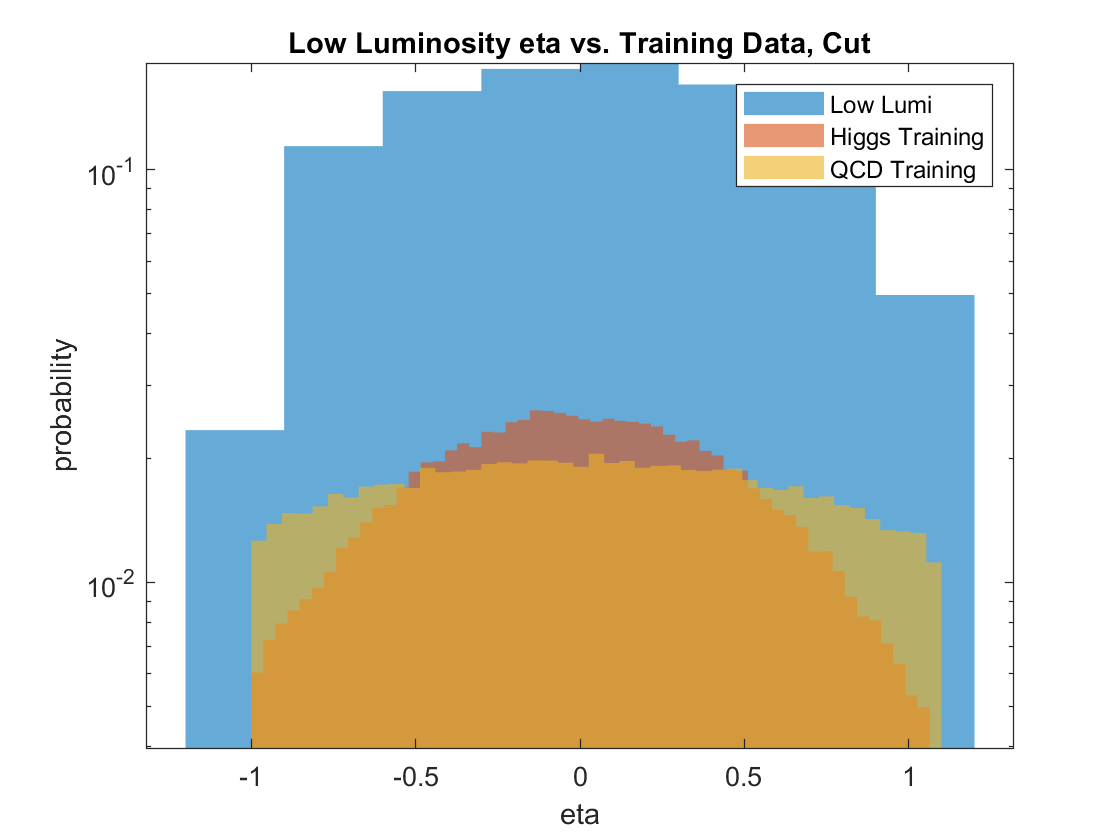

%eta
r = 2;
LL = zeros(1,442);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:442
    if (coordinates(r,1) < llumi(r,i)) && (llumi(r,i) < coordinates(r,2))
        LL(i) = llumi(r,i);
    else
        LL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

llc = rmmissing(LL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(llc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('eta')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity eta vs. Training Data, Cut')
hold off


lll = length(llumi(r,:));
lllc = length(llc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lll/lqcd;
N_sig = lllc;

SIGl(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = Nback + N_sig;
pr = cdf(poiss,signal);
SIGl(r,2) = norminv(pr)

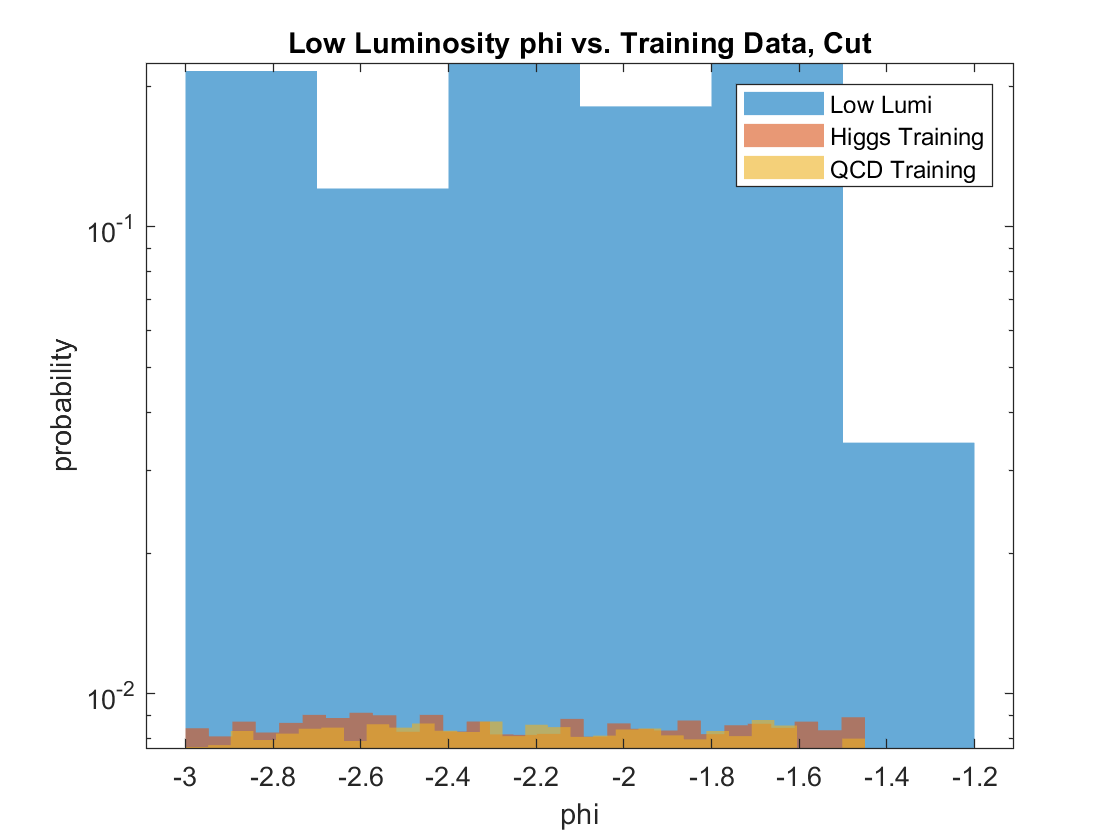

%phi
r = 3;
LL = zeros(1,442);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:442
    if (coordinates(r,1) < llumi(r,i)) && (llumi(r,i) < coordinates(r,2))
        LL(i) = llumi(r,i);
    else
        LL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

llc = rmmissing(LL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(llc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('phi')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity phi vs. Training Data, Cut')
hold off


lll = length(llumi(r,:));
lllc = length(llc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lll/lqcd;
N_sig = lllc;

SIGl(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = Nback + N_sig;
pr = cdf(poiss,signal);
SIGl(r,2) = norminv(pr)

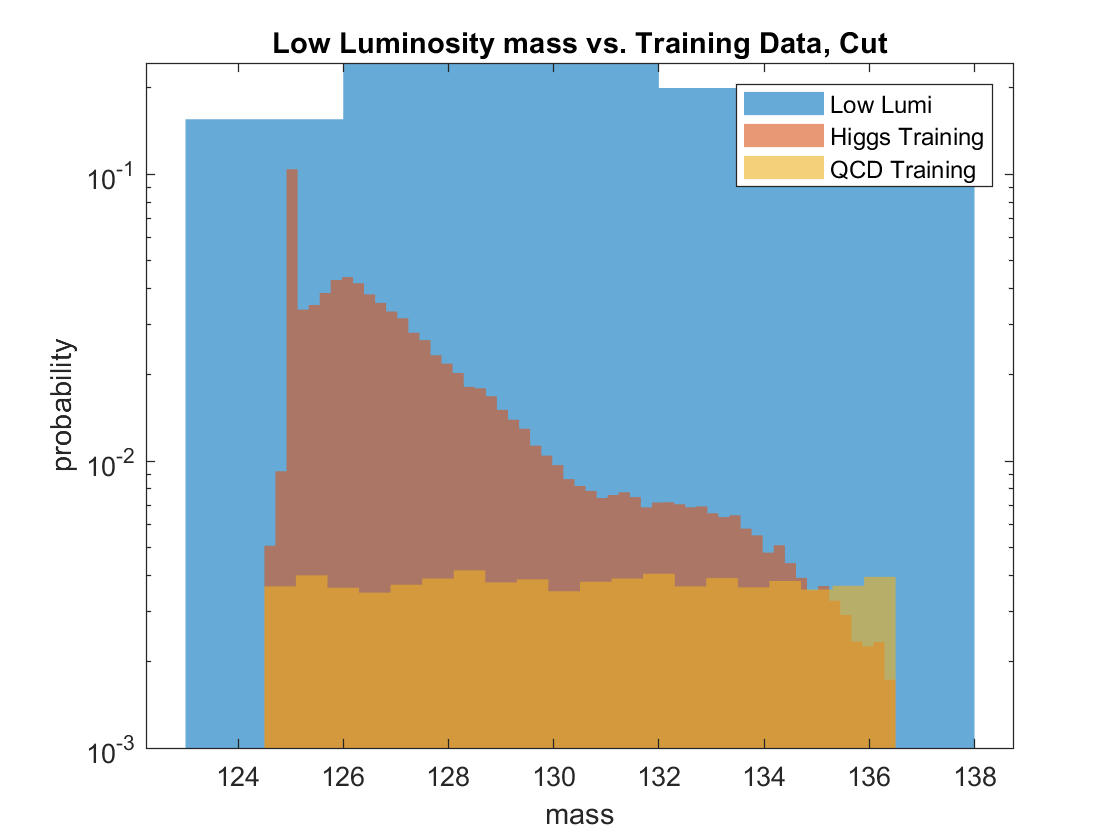

%mass
LL = zeros(1,442);
r = 4;
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:442
    if (coordinates(r,1) < llumi(r,i)) && (llumi(r,i) < coordinates(r,2))
        LL(i) = llumi(r,i);
    else
        LL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

llc = rmmissing(LL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(llc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('mass')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity mass vs. Training Data, Cut')
hold off


lll = length(llumi(r,:));
lllc = length(llc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lll/lqcd;
N_sig = lllc;

SIGl(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = Nback + N_sig;
pr = cdf(poiss,signal);
SIGl(r,2) = norminv(pr)

sigma = 6.6457

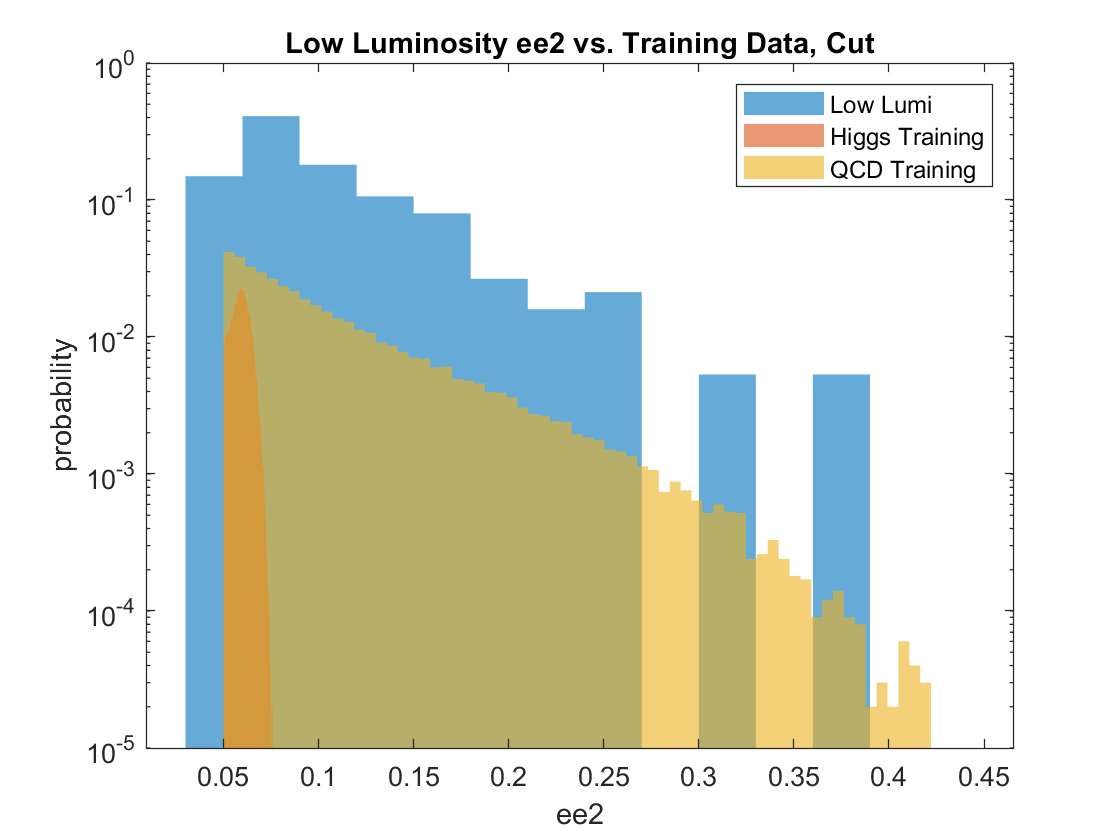

%ee2
r = 5;
LL = zeros(1,442);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:442
    if (coordinates(r,1) < llumi(r,i)) && (llumi(r,i) < coordinates(r,2))
        LL(i) = llumi(r,i);
    else
        LL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

llc = rmmissing(LL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(llc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('ee2')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity ee2 vs. Training Data, Cut')
hold off


lll = length(llumi(r,:));
lllc = length(llc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lll/lqcd;
N_sig = lllc;

SIGl(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = Nback + N_sig;
pr = cdf(poiss,signal);
SIGl(r,2) = norminv(pr)

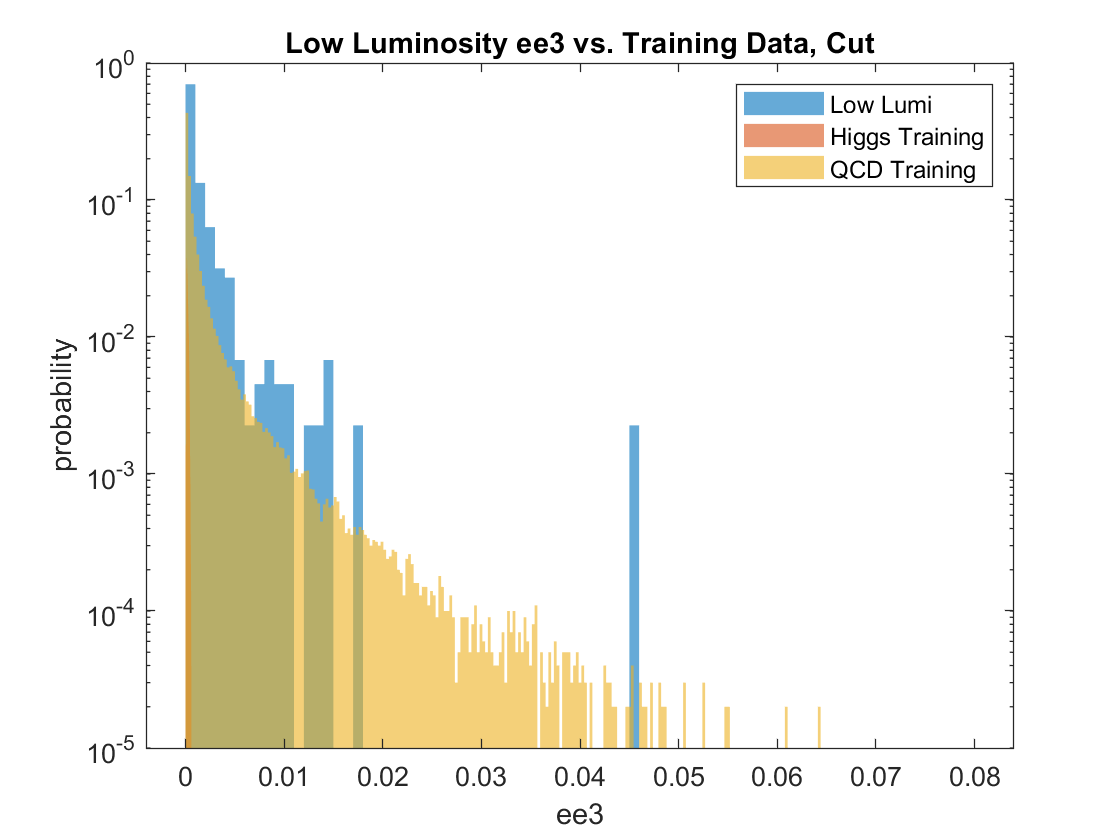

%ee3
r = 6;
LL = zeros(1,442);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:442
    if (coordinates(r,1) < llumi(r,i)) && (llumi(r,i) < coordinates(r,2))
        LL(i) = llumi(r,i);
    else
        LL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

llc = rmmissing(LL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(llc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('ee3')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity ee3 vs. Training Data, Cut')
hold off


lll = length(llumi(r,:));
lllc = length(llc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lll/lqcd;
N_sig = lllc;

SIGl(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = Nback + N_sig;
pr = cdf(poiss,signal);
SIGl(r,2) = norminv(pr)

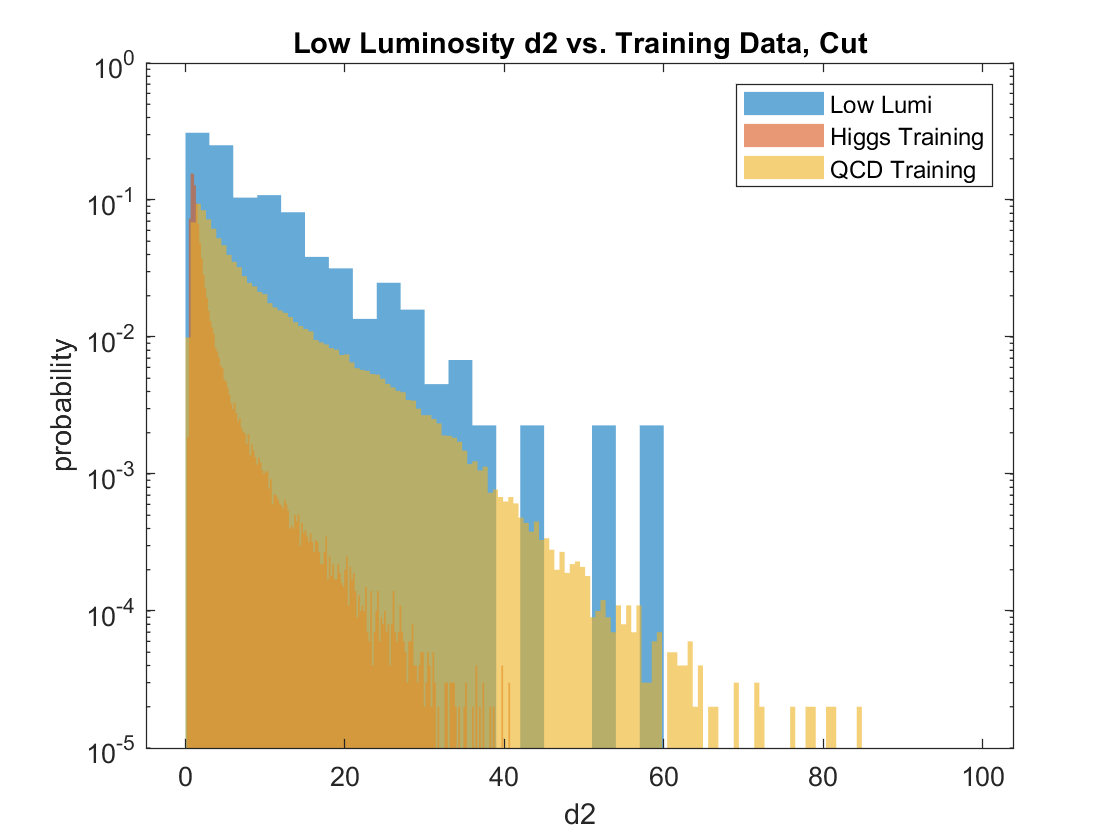

%d2
r = 7;
LL = zeros(1,442);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:442
    if (coordinates(r,1) < llumi(r,i)) && (llumi(r,i) < coordinates(r,2))
        LL(i) = llumi(r,i);
    else
        LL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

llc = rmmissing(LL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(llc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('d2')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity d2 vs. Training Data, Cut')
hold off


lll = length(llumi(r,:));
lllc = length(llc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lll/lqcd;
N_sig = lllc;

SIGl(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = Nback + N_sig;
pr = cdf(poiss,signal);
SIGl(r,2) = norminv(pr)

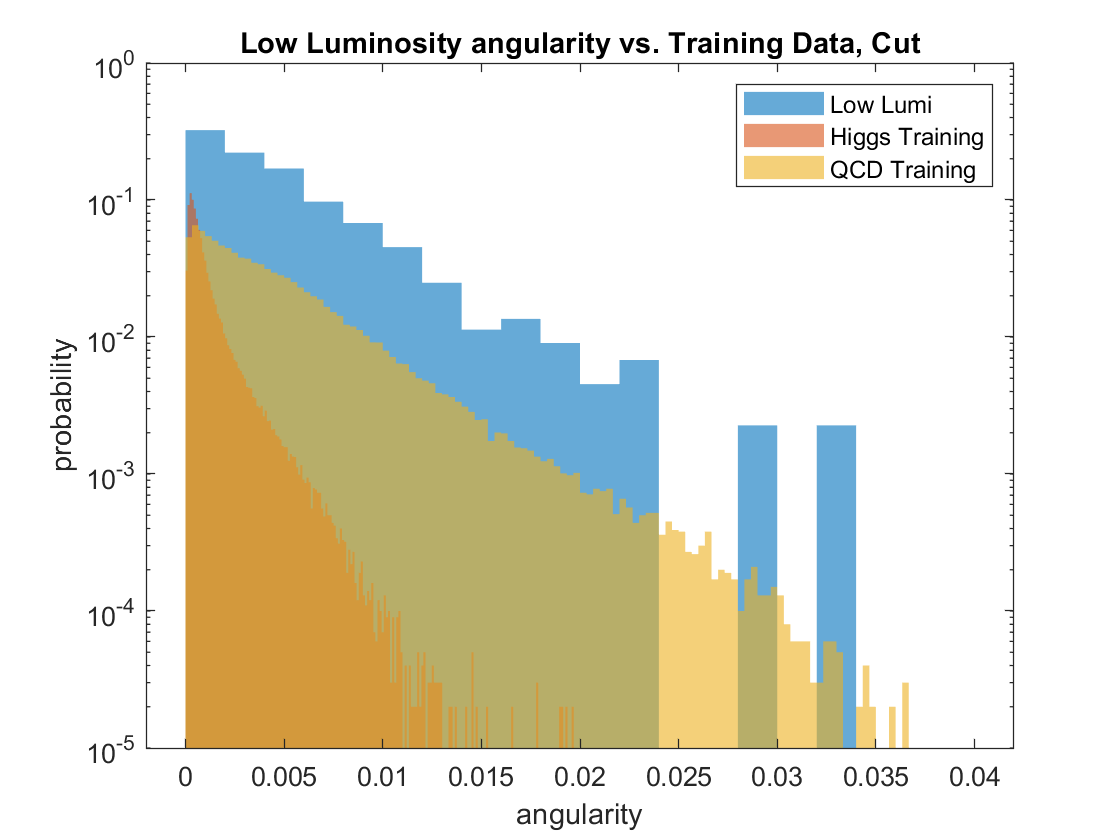

%angularity
r = 8;
LL = zeros(1,442);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:442
    if (coordinates(r,1) < llumi(r,i)) && (llumi(r,i) < coordinates(r,2))
        LL(i) = llumi(r,i);
    else
        LL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

llc = rmmissing(LL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(llc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('angularity')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity angularity vs. Training Data, Cut')
hold off


lll = length(llumi(r,:));
lllc = length(llc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lll/lqcd;
N_sig = lllc;

SIGl(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = Nback + N_sig;
pr = cdf(poiss,signal);
SIGl(r,2) = norminv(pr)

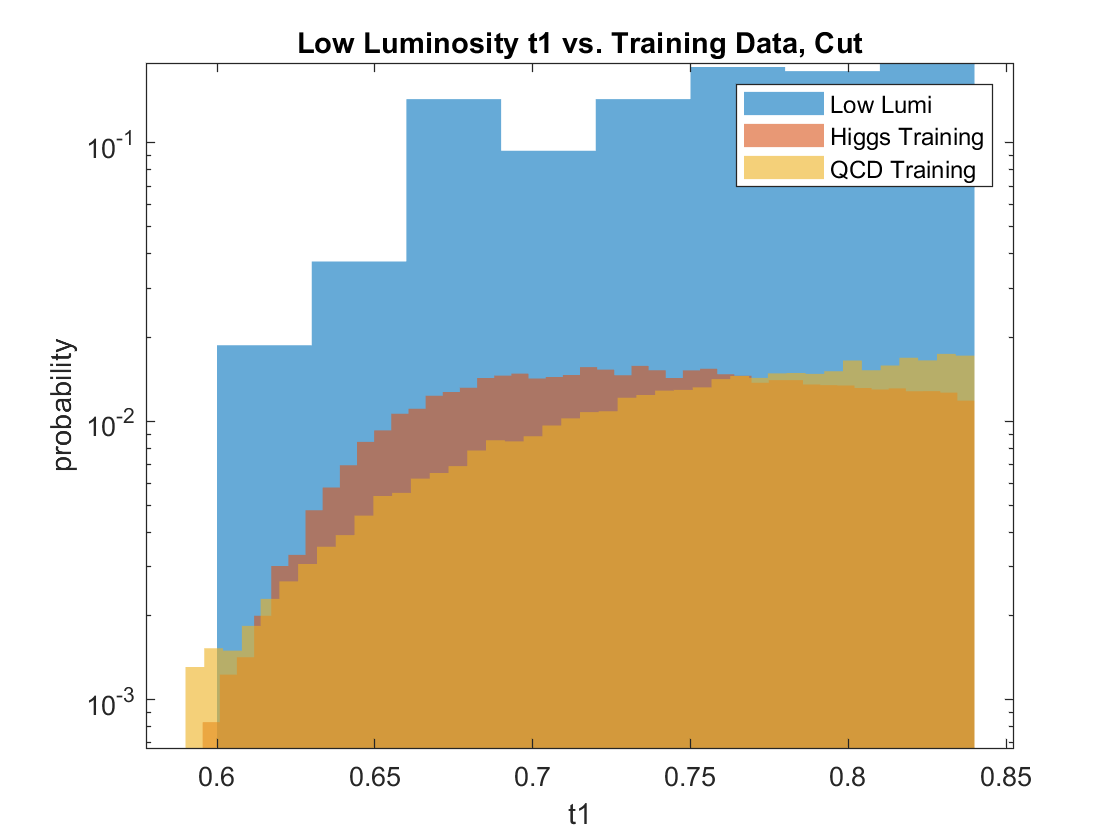

%t1
r = 9;
LL = zeros(1,442);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:442
    if (coordinates(r,1) < llumi(r,i)) && (llumi(r,i) < coordinates(r,2))
        LL(i) = llumi(r,i);
    else
        LL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

llc = rmmissing(LL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(llc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('t1')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity t1 vs. Training Data, Cut')
hold off


lll = length(llumi(r,:));
lllc = length(llc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lll/lqcd;
N_sig = lllc;

SIGl(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = Nback + N_sig;
pr = cdf(poiss,signal);
SIGl(r,2) = norminv(pr)

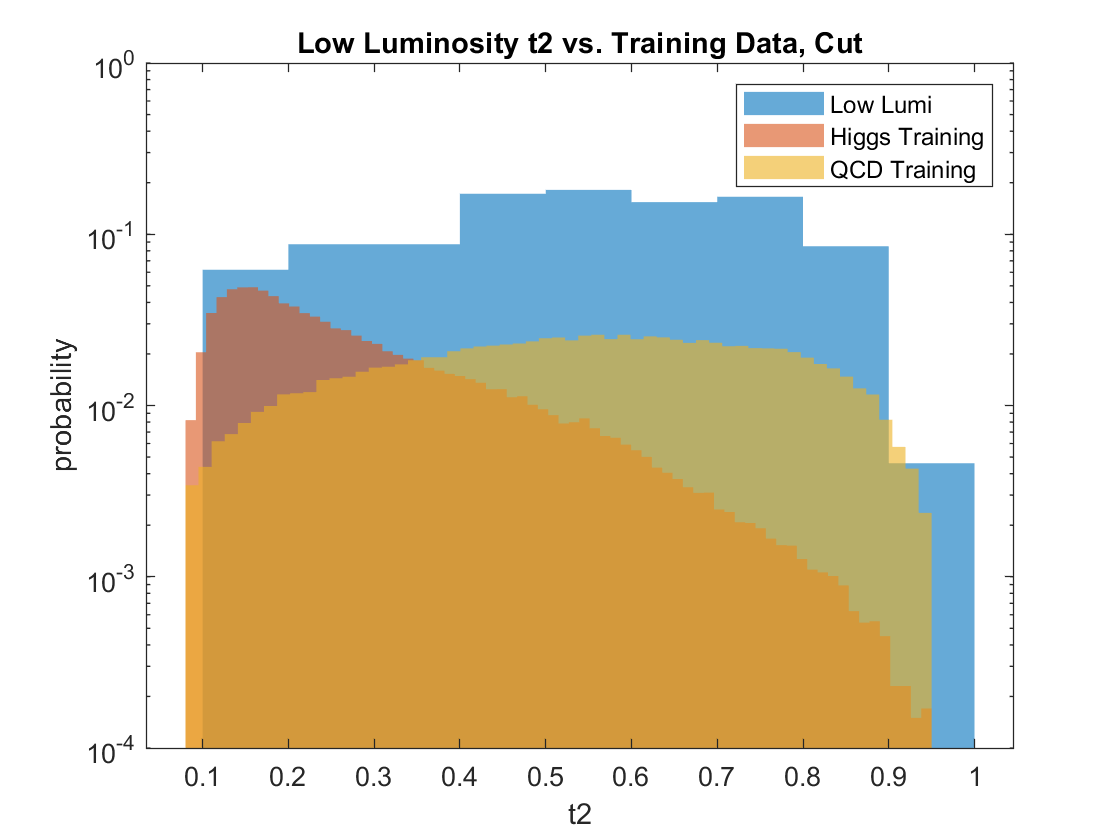

%t2
r = 10;
LL = zeros(1,442);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:442
    if (coordinates(r,1) < llumi(r,i)) && (llumi(r,i) < coordinates(r,2))
        LL(i) = llumi(r,i);
    else
        LL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

llc = rmmissing(LL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(llc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('t2')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity t2 vs. Training Data, Cut')
hold off


lll = length(llumi(r,:));
lllc = length(llc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lll/lqcd;
N_sig = lllc;

SIGl(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = Nback + N_sig;
pr = cdf(poiss,signal);
SIGl(r,2) = norminv(pr)

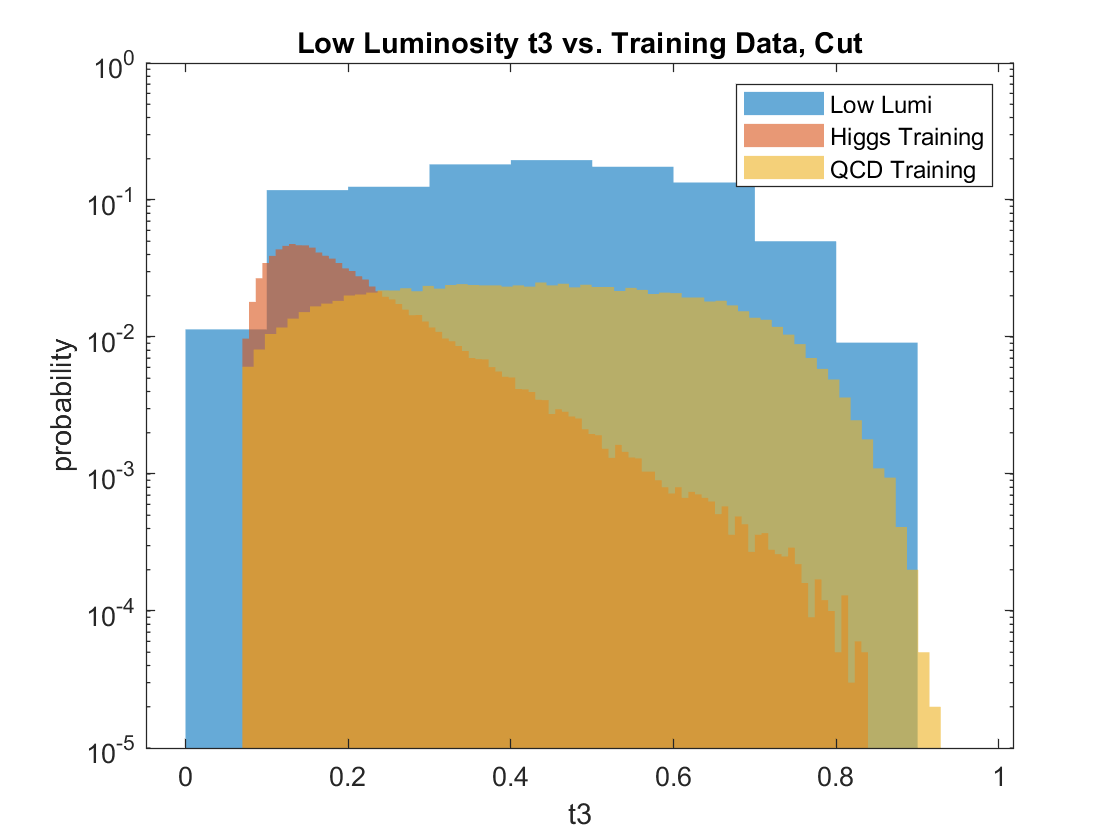

%t3
r = 11;
LL = zeros(1,442);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:442
    if (coordinates(r,1) < llumi(r,i)) && (llumi(r,i) < coordinates(r,2))
        LL(i) = llumi(r,i);
    else
        LL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

llc = rmmissing(LL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(llc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('t3')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity t3 vs. Training Data, Cut')
hold off


lll = length(llumi(r,:));
lllc = length(llc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lll/lqcd;
N_sig = lllc;

SIGl(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = Nback + N_sig;
pr = cdf(poiss,signal);
SIGl(r,2) = norminv(pr)

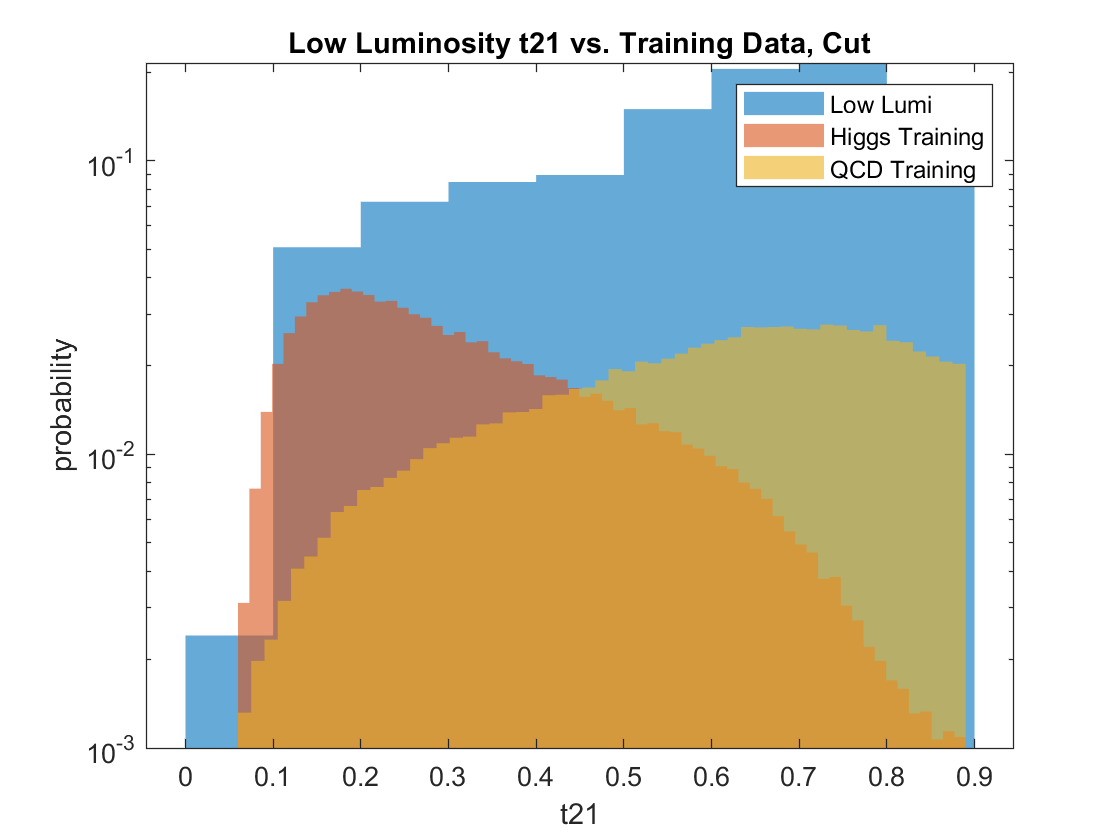

%t21
r = 12;
LL = zeros(1,442);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:442
    if (coordinates(r,1) < llumi(r,i)) && (llumi(r,i) < coordinates(r,2))
        LL(i) = llumi(r,i);
    else
        LL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

llc = rmmissing(LL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(llc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('t21')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity t21 vs. Training Data, Cut')
hold off


lll = length(llumi(r,:));
lllc = length(llc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lll/lqcd;
N_sig = lllc;

SIGl(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = Nback + N_sig;
pr = cdf(poiss,signal);
SIGl(r,2) = norminv(pr)

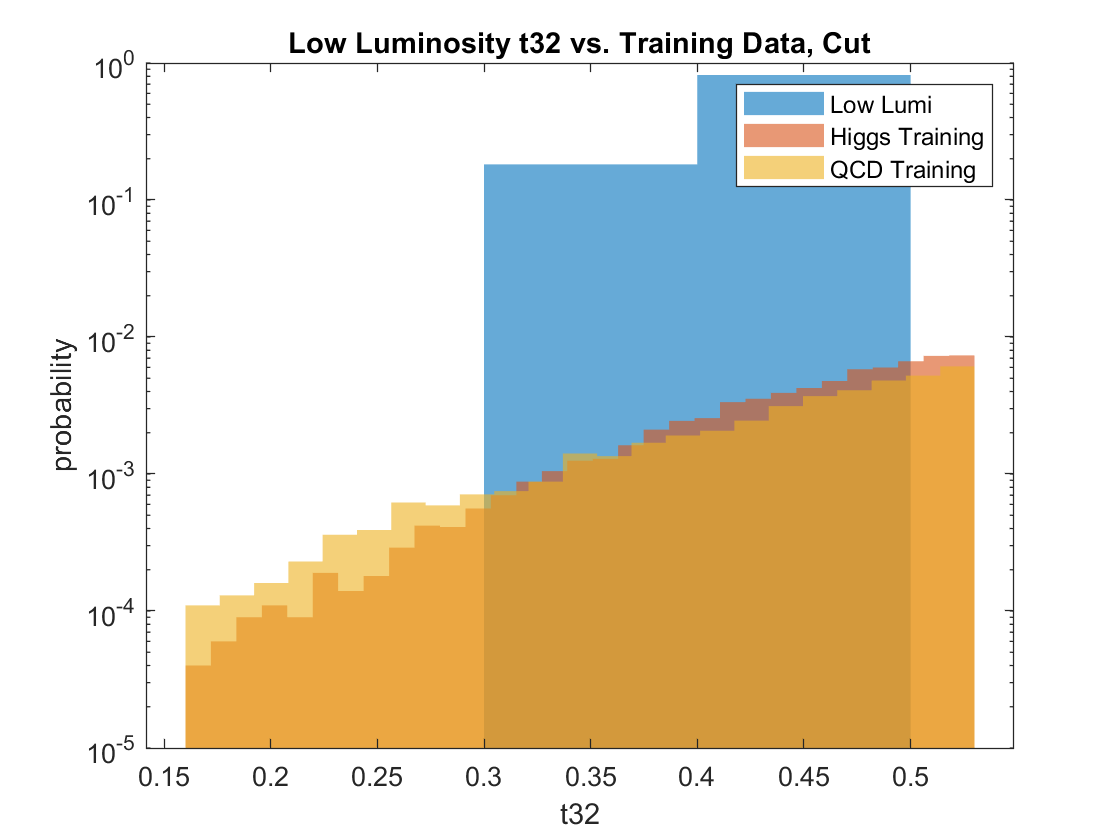

%t32
r = 13;
LL = zeros(1,442);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:442
    if (coordinates(r,1) < llumi(r,i)) && (llumi(r,i) < coordinates(r,2))
        LL(i) = llumi(r,i);
    else
        LL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

llc = rmmissing(LL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(llc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('t32')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity t32 vs. Training Data, Cut')
hold off


lll = length(llumi(r,:));
lllc = length(llc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lll/lqcd;
N_sig = lllc;

SIGl(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = Nback + N_sig;
pr = cdf(poiss,signal);
SIGl(r,2) = norminv(pr)

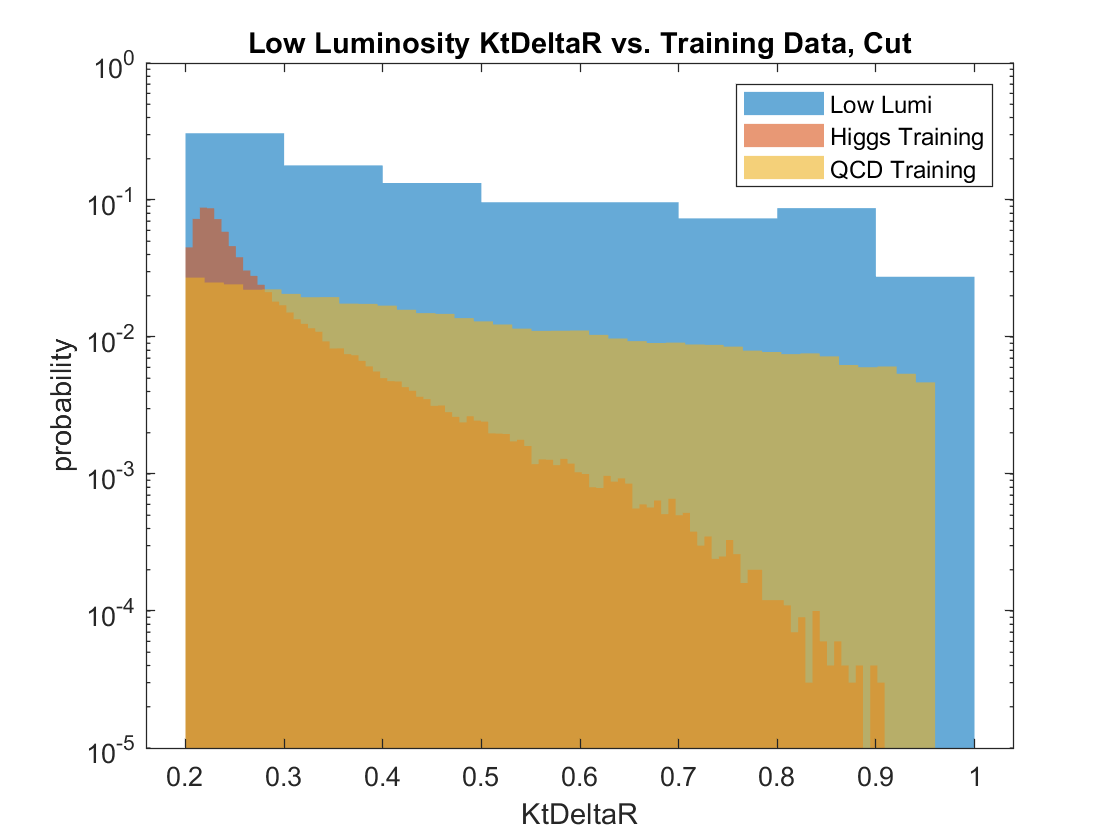

%KtDeltaR
r = 14;
LL = zeros(1,442);
QCD = zeros(1,length(qcd(r,:)));
HIG = zeros(1,length(higgs(r,:)));

for i = 1:442
    if (coordinates(r,1) < llumi(r,i)) && (llumi(r,i) < coordinates(r,2))
        LL(i) = llumi(r,i);
    else
        LL(i) = NaN;
    end
end

for j = 1:length(qcd(r,:))
    if (coordinates(r,1) < qcd(r,j)) && (qcd(r,j) < coordinates(r,2))
        QCD(j) = qcd(r,j);
    else
        QCD(j) = NaN;
    end
    if (coordinates(r,1) < higgs(r,j)) && (higgs(r,j) < coordinates(r,2))
        HIG(j) = higgs(r,j);
    else
        HIG(j) = NaN;
    end   
end

llc = rmmissing(LL);
qcdc = rmmissing(QCD);
higc = rmmissing(HIG);

histogram(llc,'Normalization','probability','EdgeColor','none')
hold on 
histogram(higgs(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
histogram(qcd(r,:),'Normalization','probability','EdgeColor','none','BinLimits',[coordinates(r,1),coordinates(r,2)])
set(gca,'Yscale','log')
xlabel('KtDeltaR')
ylabel('probability')
legend('Low Lumi','Higgs Training','QCD Training')
title('Low Luminosity KtDeltaR vs. Training Data, Cut')
hold off


lll = length(llumi(r,:));
lllc = length(llc);
lqcd = length(qcd(r,:));
lqcdc = length(qcdc);
lhig = length(higgs(r,:));
lhigc = length(higc);

N_higc = lhigc*Nhiggs/lhig;
N_qcdc = lqcdc*Nqcd/lqcd;

Nback = lqcdc*lll/lqcd;
N_sig = lllc;

SIGl(r,1) = N_higc/sqrt(N_qcdc);
poiss = makedist("Poisson","lambda",Nback);
signal = Nback + N_sig;
pr = cdf(poiss,signal);
SIGl(r,2) = norminv(pr)

SIGl

SIGl =     0.3892   18.9579         0         0         0         0         0         0         0         0         0         0         0         0
    1.2047   40.3769         0         0         0         0         0         0         0         0         0         0         0         0
    0.5574   24.1998         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.1567   29.9276         0         0         0         0         0         0         0         0         0         0         0         0
    1.1180   45.8399         0         0         0         0         0         0         0         0         0         0         0         0
    1.1181   45.8403         0         0         0         0         0         0         0         0         0         0         0         0
    1.

3)95% Confidence Level of signal yields

- In the low luminosity data, the observed significance is less than 5σσ. We will calculate the 95% confidence level upper limit of signal yield.

- Evaluate the expected 95% confidence level upper limit

- Evaluate the observed 95% confidence level upper limit

- Compare expectation to observation. Comment on your finding.

4)Bonus:

- Evalute the 1σσ uncertainty of the expected 95% confidence level upper limit.